# ECE 808 Smart Water Networks

## Modelling Water Distribution Networks using EPANET

## **Introduction to EPANET**

- Created in 1993 by Lew Rossman, version 2 in 2000.

- Released in the public domain by the US EPA.

- Designed as a research tool to better understand the dynamics of water quality.

- Solves flows, pressures and water quality for a certain period of time.

- Since v2 it can be linked with external software.

- Links with a graphical interface.

- Extended capabilities with EPANET-MSX

- Now open source from the Open Water Analytics community, Version 2.2

## Setting up EPANET-MATLAB Toolkit

### **How to ask for help**

There is an online community, which is actively supported by KIOS. You can ask for comments and help at [http://community.wateranalytics.org](http://community.wateranalytics.org)

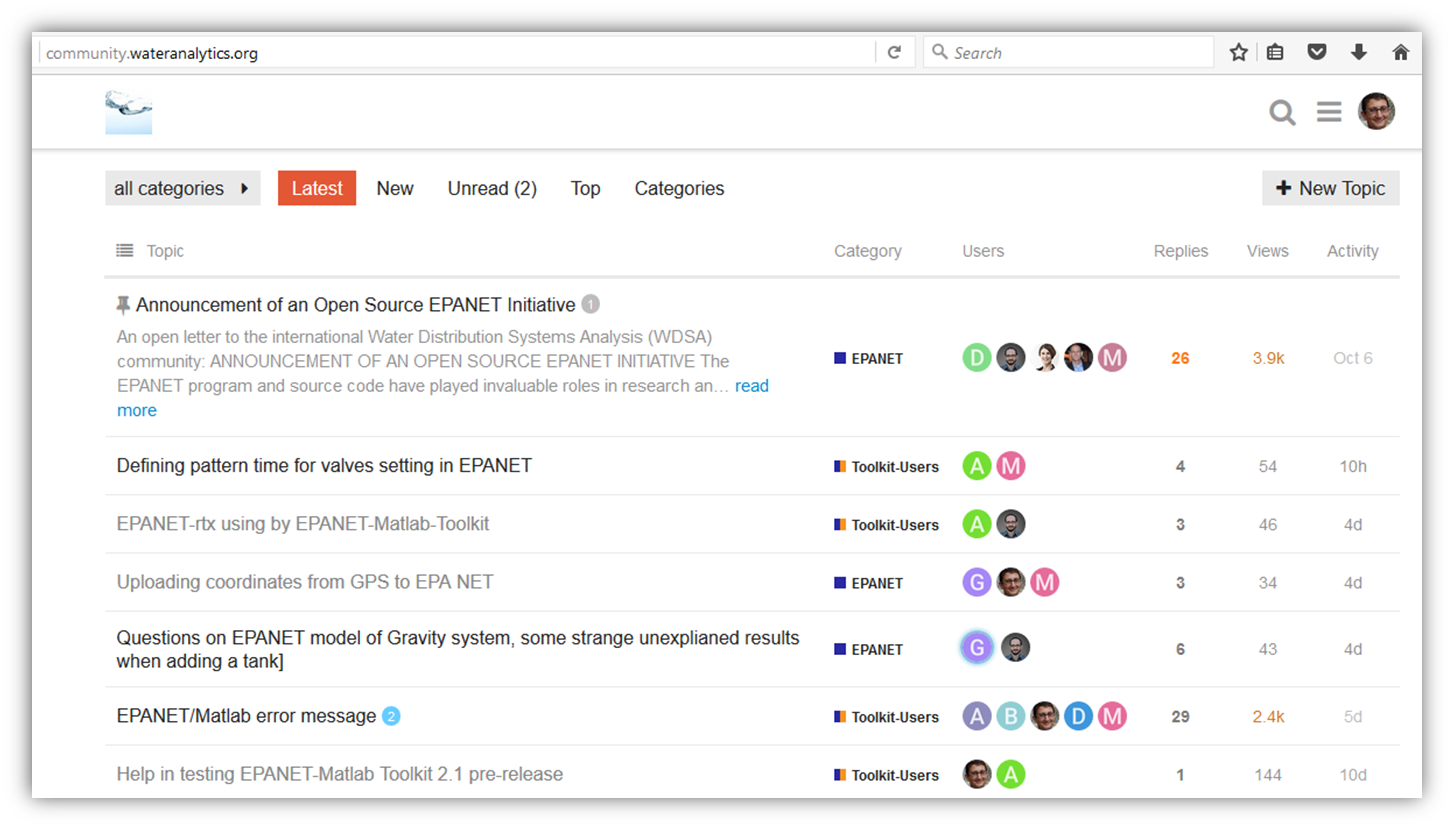

### **Download **

You can download the latest version from [https://github.com/OpenWaterAnalytics/EPANET-Matlab-Toolkit/releases](https://github.com/OpenWaterAnalytics/EPANET-Matlab-Toolkit/releases)

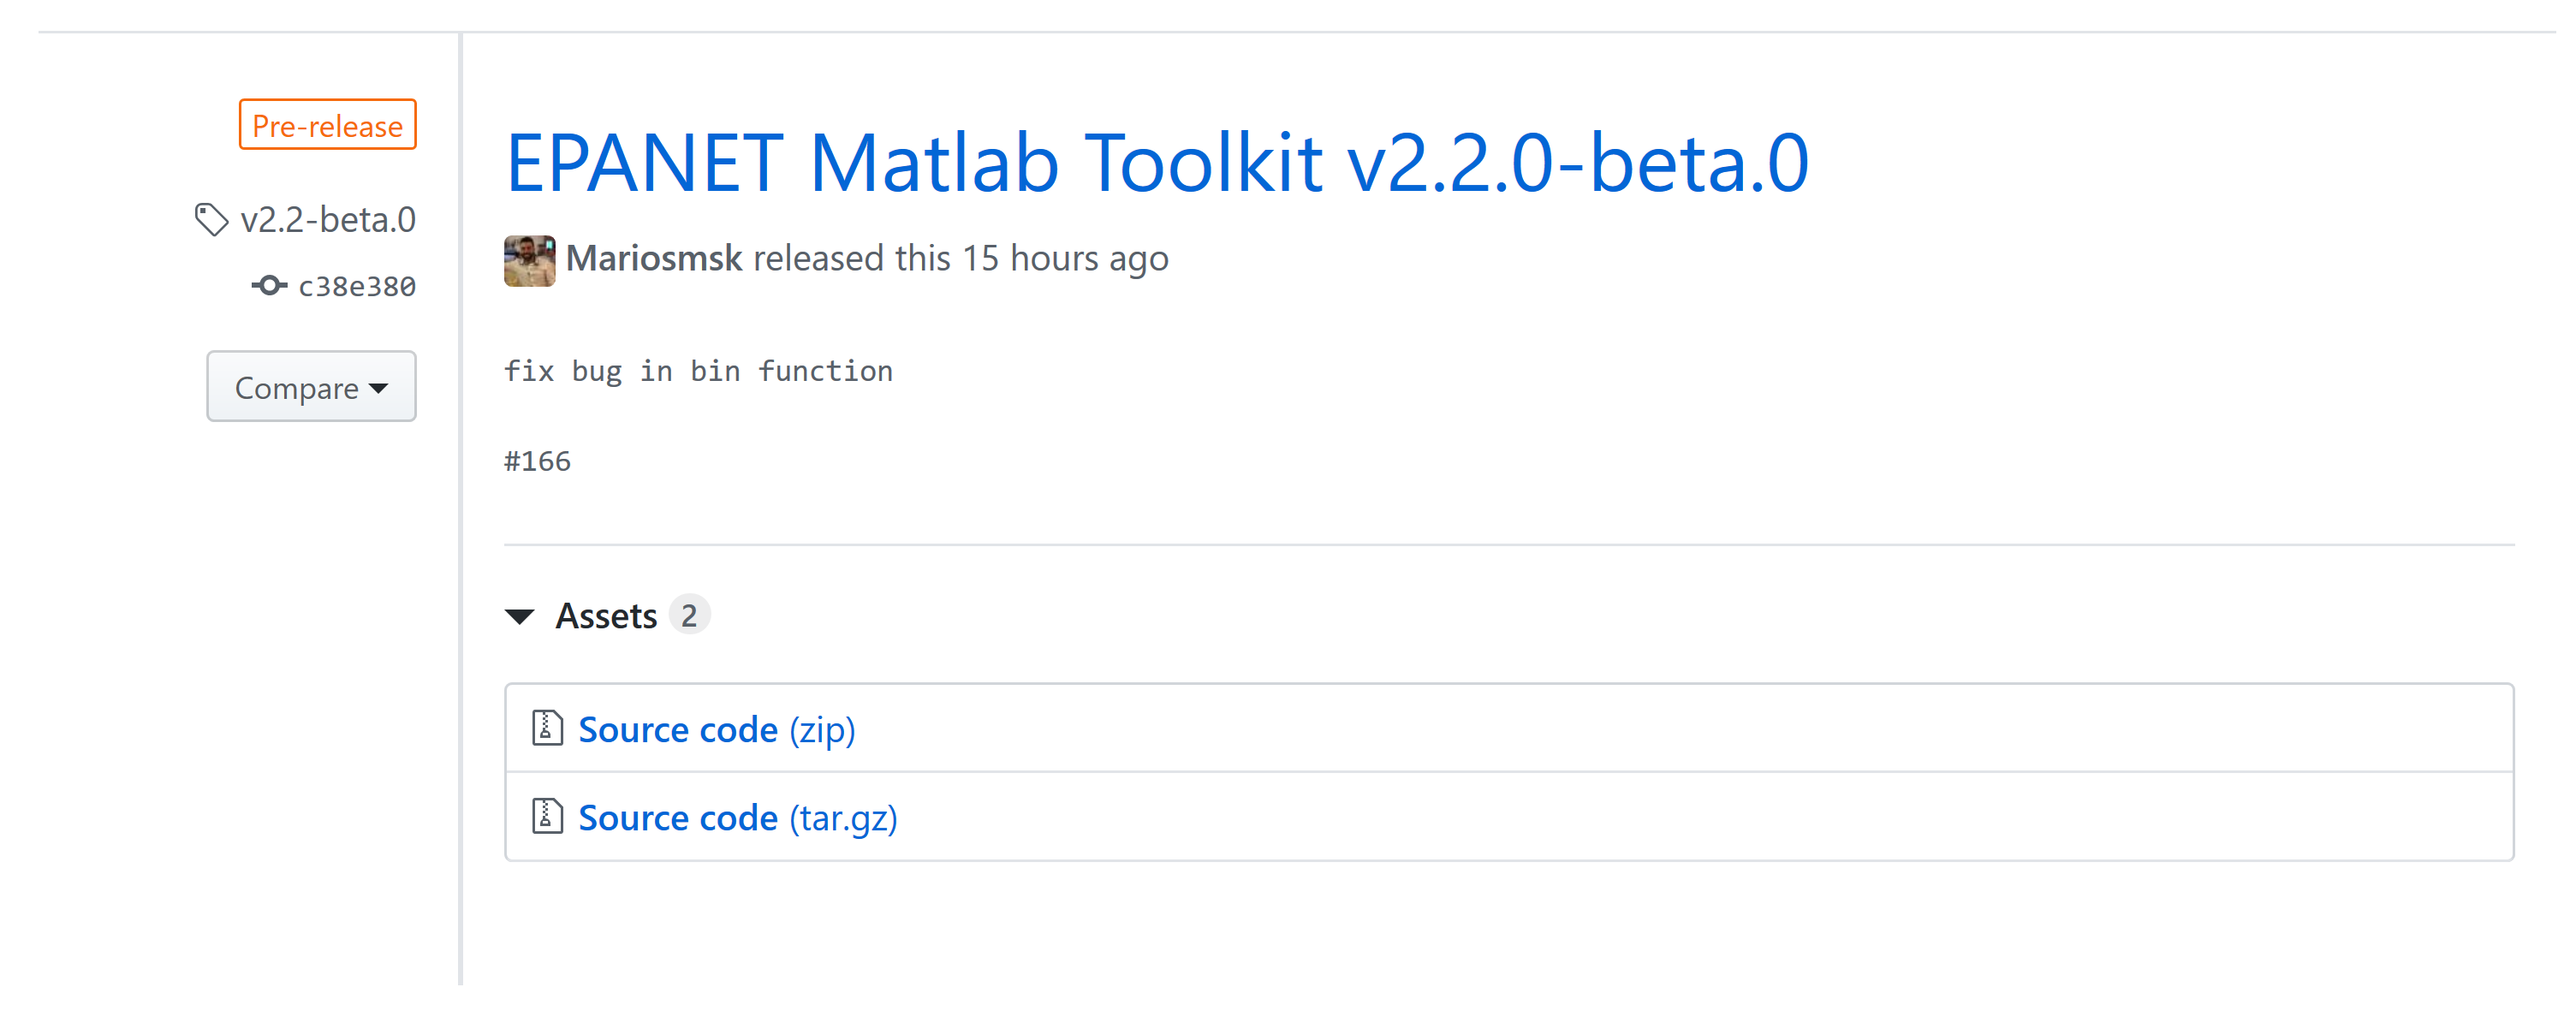

### **Stucture of the Toolkit**

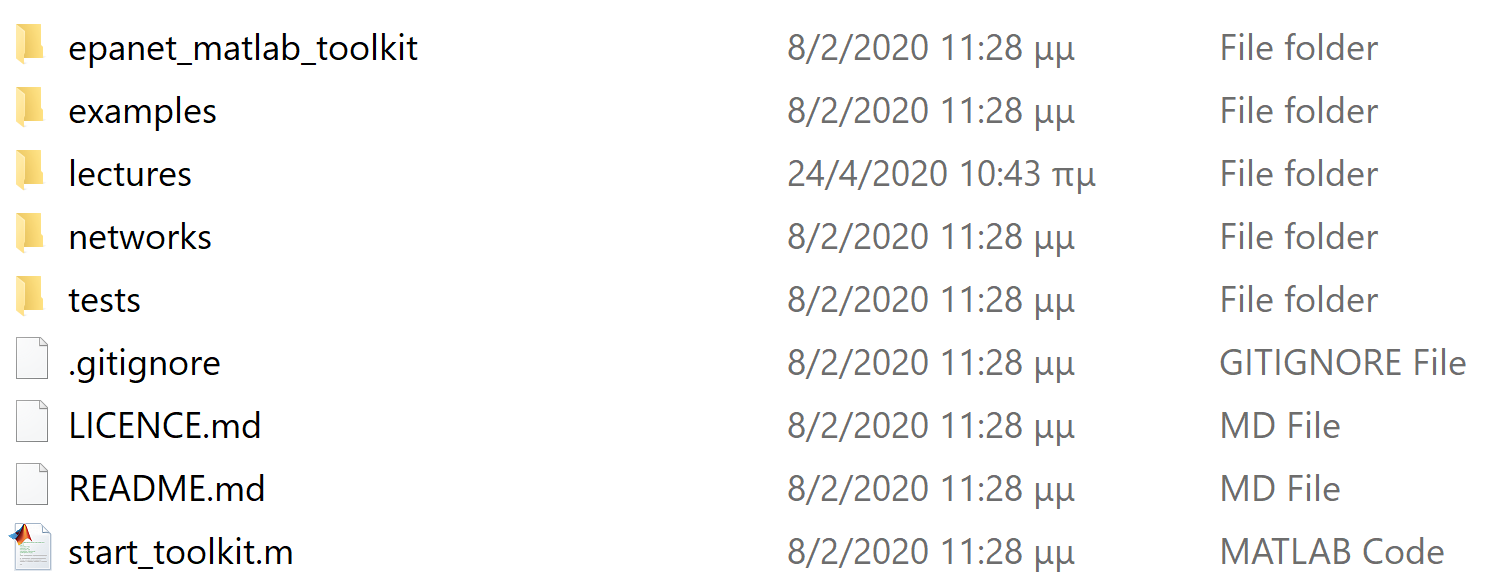

### **Installation of the MinGW-w64 Compiler for MATLAB**

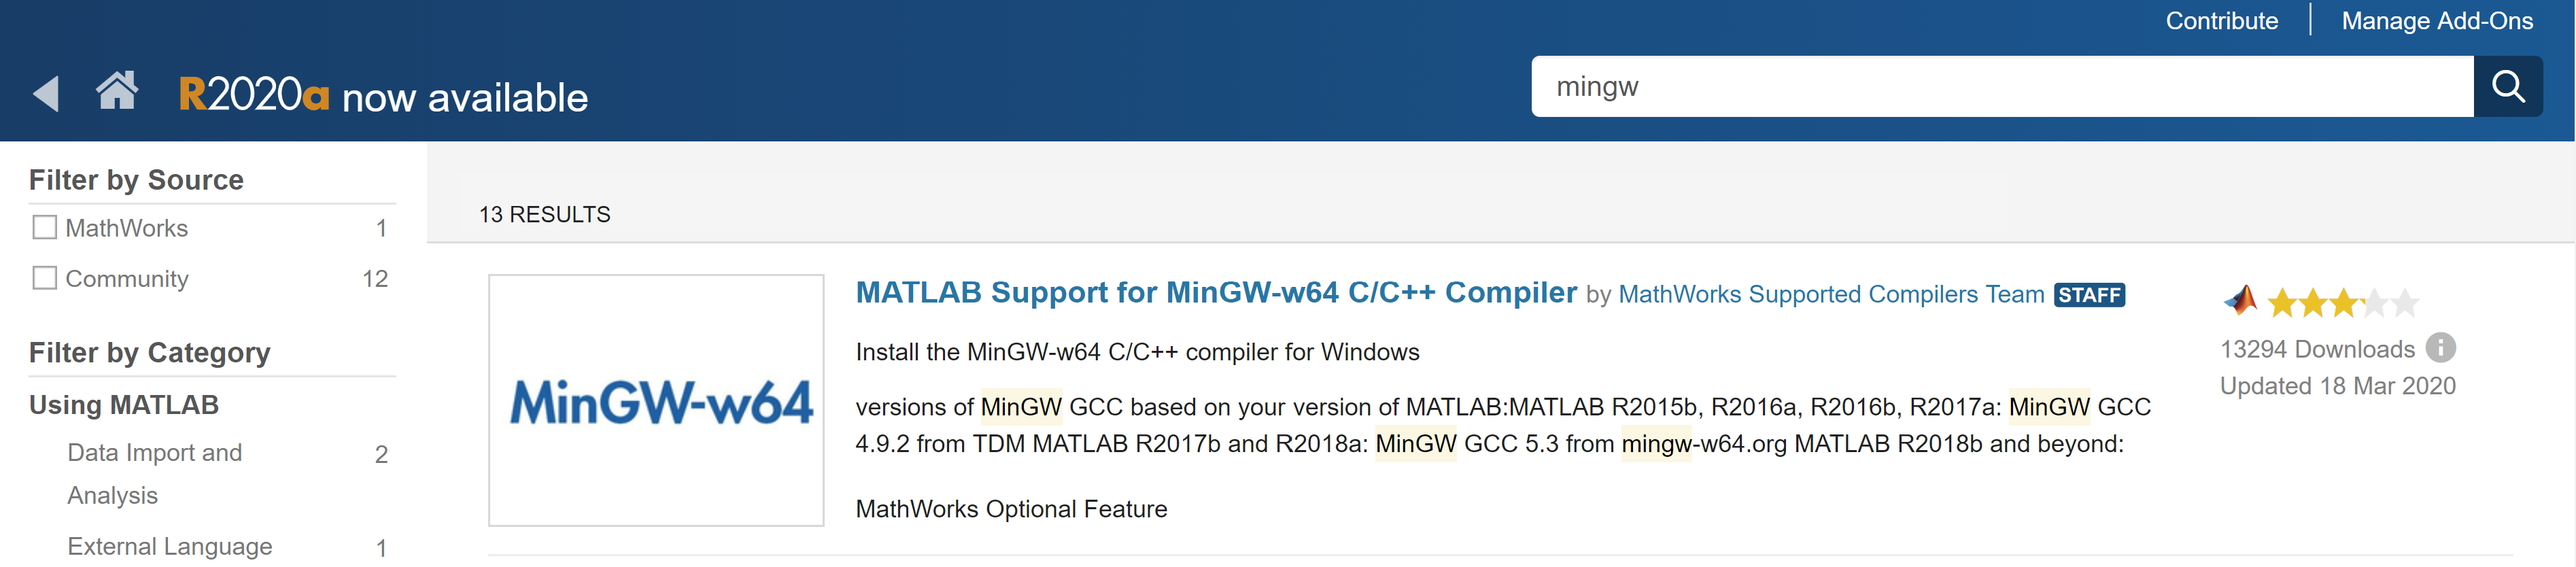

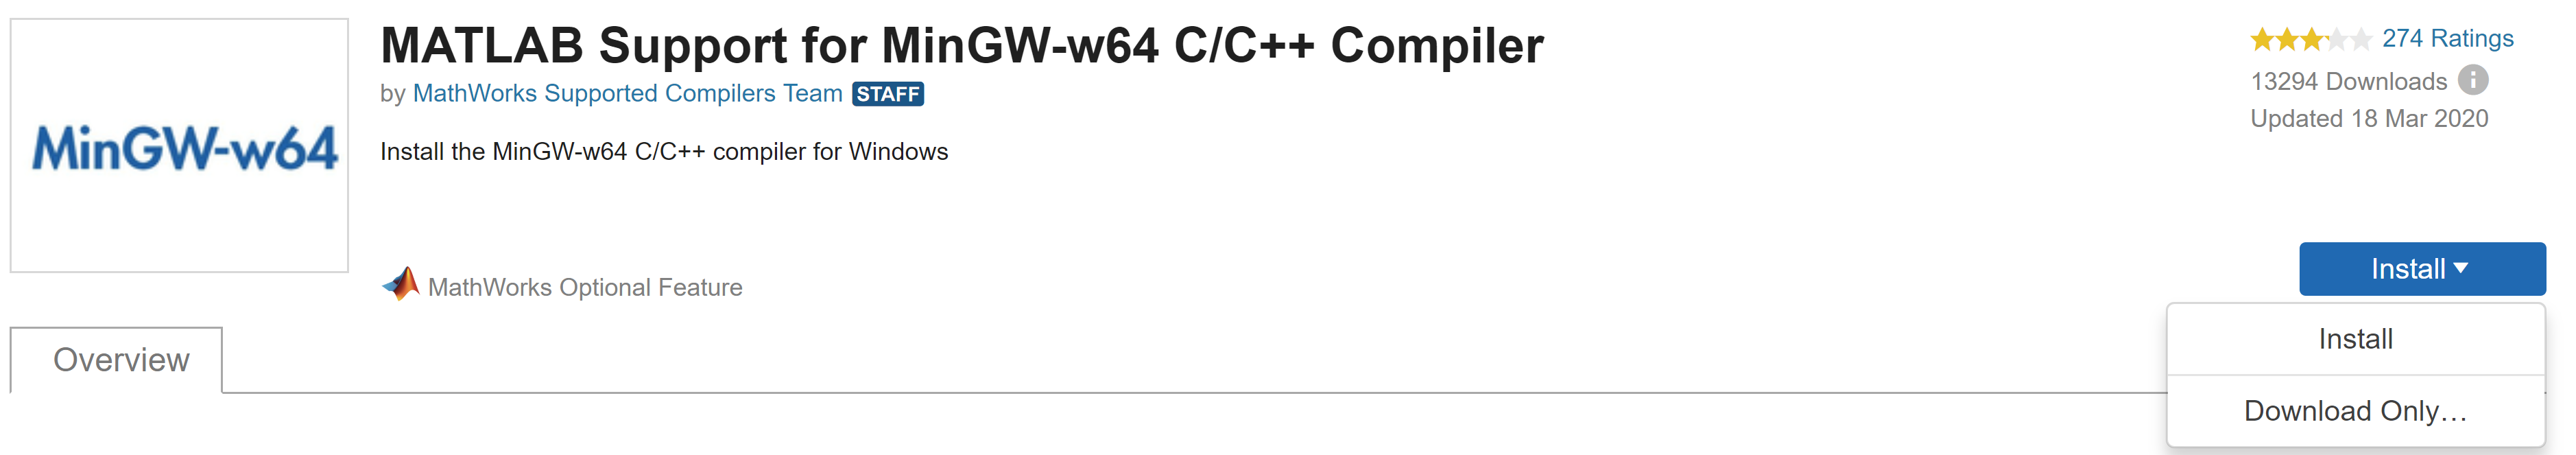

mex -setup

EPANET-MATLAB Toolkit Paths Loaded.


`If this has been correctily configured, you should see the following:`

`MEX configured to use 'MinGW64 Compiler (C)' for C language compilation.`

`To choose a different language, select one from the following:`

` mex -setup C++ `

` mex -setup FORTRAN`

**Install  Compiler Error Message**

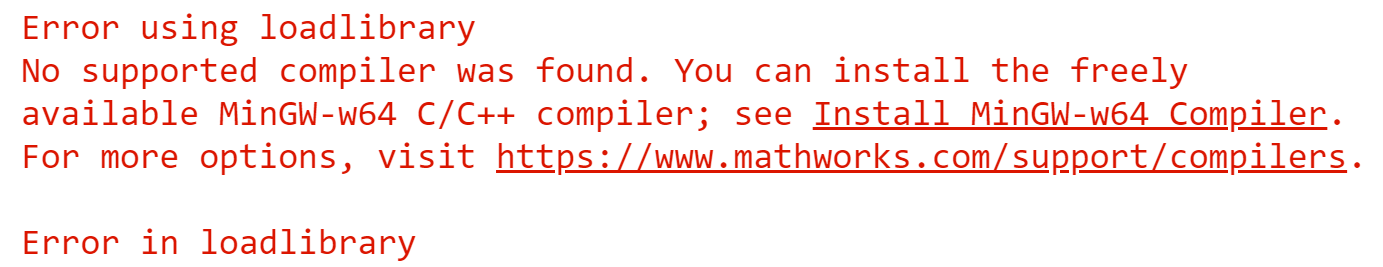

### **Initialize EPANET-MATLAB Toolkit**

Load all the paths in MATLAB. You should always begin with this command to load the toolkit.

start_toolkit

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "net2-cl2.inp"...
Input File "net2-cl2.inp" loaded sucessfuly.


G =   epanet with properties:

                   ControlLevelValues: []
                     ControlLinkIndex: []
                     ControlNodeIndex: []
                         ControlRules: []
                    ControlRulesCount: 0
                             Controls: [1×1 struct]
                      ControlSettings: []
                         ControlTypes: {}
                    ControlTypesIndex: []
                           CurveCount: 0
                           CurvesInfo: [1×1 struct]
                      DemandModelCode: 0
                      DemandModelPmin: 0
                      DemandModelPreq: 0.1000
                      DemandModelPexp: 0.5000
                      DemandModelType: {'DDA'}
                EnergyEfficiencyUnits: 'percent'
                          EnergyUnits: 'kwatt-hours'
                              Errcode: 0
                            InputFile: 'C:\Users\eldemet\Deskt

If you get an error message:

`'start_toolkit' is not found in the current folder or on the MATLAB path, but exists in:`

It means that you need to change the MATLAB current folder.

**Load a benchmark network**

Decide which benchmark network to use and load the network

% decide which network to load from the "/networks/" folder  
filename = 'net2-cl2.inp'; % you can also try 'L-TOWN.inp', 'Net3.inp', etc.

%call epanet class and load all data and functions in G structure
G = epanet(filename)


Properties for class epanet:

    ControlLevelValues
    ControlLinkIndex
    ControlNodeIndex
    ControlRules
    ControlRulesCount
    Controls
    ControlSettings
    ControlTypes
    ControlTypesIndex
    CurveCount
    CurvesInfo
    DemandModelCode
    DemandModelPmin
    DemandModelPreq
    DemandModelPexp
    DemandModelType
    EnergyEfficiencyUnits
    EnergyUnits
    Errcode
    InputFile
    Iterations
    LibEPANET
    LibEPANETpath
    libFunctions
    LinkBulkReactionCoeff
    LinkCount
    LinkDiameter
    LinkFlowUnits
    LinkFrictionFactorUnits
    LinkIndex
    LinkInitialSetting
    LinkInitialStatus
    LinkLength
    LinkLengthsUnits
    LinkLengthUnits
    LinkMinorLossCoeff
    LinkMinorLossCoeffUnits
    LinkNameID
    LinkPipeCount
    LinkPipeDiameterUnits
    LinkPipeIndex
    LinkPipeNameID
    LinkPipeRoughnessCoeffUnits
    LinkPumpCount
    LinkPumpHeadCurveIndex
    LinkPumpIndex
    LinkPumpNameID
    LinkPumpPatternIndex
    LinkPumpPatternNameID
 


Methods for class epanet:

BinClose                                     
BinUpdateClass                               
Binplot                                      
addBinCVPipe                                 
addBinControl                                
addBinCurveEfficiency                        
addBinCurveHeadloss                          
addBinCurvePump                              
addBinCurveVolume                            
addBinLinkPipe                               
addBinLinkPump                               
addBinLinkValve                              
addBinLinkVertices                           
addBinNodeJunction                           
addBinNodeReservoir                          
addBinNodeTank                               
addBinPattern                                
addBinPipe                                   
addBinPump                                   
addBinValveFCV                               
addBinValveGPV                               
addBin

pipeCount = int32
40

## How to use the EPANET-MATLAB Toolkit

### Data and Methods in Toolkit

What data variables are in the class?

properties(G)

diameters =     12    12     8     8    12    12    12    12    12     8    12    12    12    12    12     8     8     8    12    12     8    12     8     8     8    12    12    12    12    12     8     8     8     8     8     8     8     8     8     8


pipelength =         2400         800        1300


What methods/functions are in the toolkit?

methods(G)

pipeNameID = 1×40 cell array
    {'1'}    {'2'}    {'3'}    {'4'}    {'5'}    {'6'}    {'7'}    {'8'}    {'9'}    {'10'}    {'11'}    {'12'}    {'13'}    {'14'}    {'15'}    {'16'}    {'17'}    {'18'}    {'19'}    {'20'}    {'21'}    {'22'}    {'23'}    {'24'}    {'25'}    {'26'}    {'27'}    {'28'}    {'29'}    {'30'}    {'31'}    {'32'}    {'34'}    {'35'}    {'36'}    {'37'}    {'38'}    {'39'}    {'40'}    {'41'}


### **Getting information from pipes**

pipeCount = G.getLinkCount

nodeCount = int32
36

diameters = G.getLinkDiameter

elevations =     50   100    60


pipelength = G.getLinkLength(1:3)

demands = 1×1 cell array
    {1×36 double}


pipeNameID = G.getLinkNameID

nodeID = 1×36 cell array
    {'1'}    {'2'}    {'3'}    {'4'}    {'5'}    {'6'}    {'7'}    {'8'}    {'9'}    {'10'}    {'11'}    {'12'}    {'13'}    {'14'}    {'15'}    {'16'}    {'17'}    {'18'}    {'19'}    {'20'}    {'21'}    {'22'}    {'23'}    {'24'}    {'25'}    {'27'}    {'28'}    {'29'}    {'30'}    {'31'}    {'32'}    {'33'}    {'34'}    {'35'}    {'36'}    {'26'}


### **Getting information from nodes**

nodeCount = G.getNodeCount

d4 = 8

elevations = G.getNodeElevations([1, 2, 3])

diameters =     12    12     8    10    12    12    12    12    12     8    12    12    12    12    12     8     8     8    12    12     8    12     8     8     8    12    12    12    12    12     8     8     8     8     8     8     8     8     8     8


demands = G.getNodeBaseDemands
nodeID = G.getNodeNameID

d4new = 10

### **Change parameters in network**

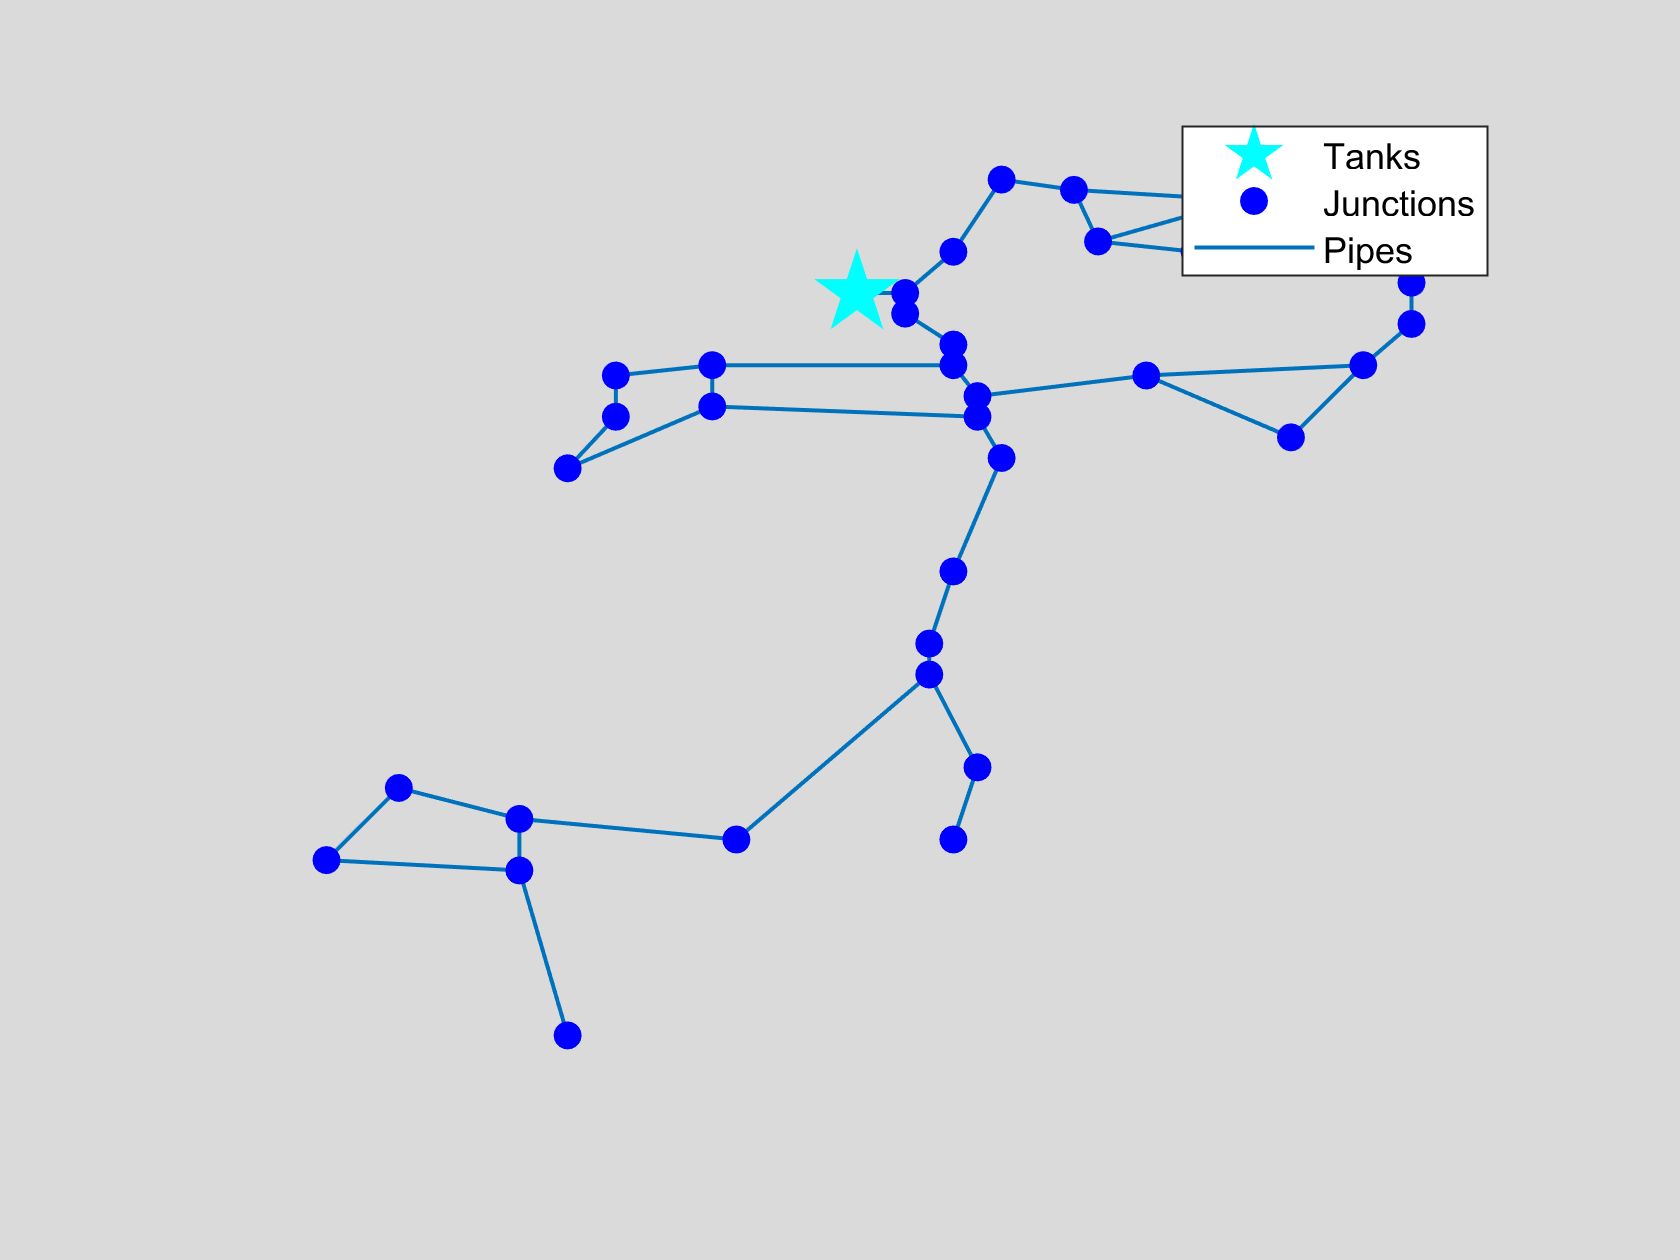

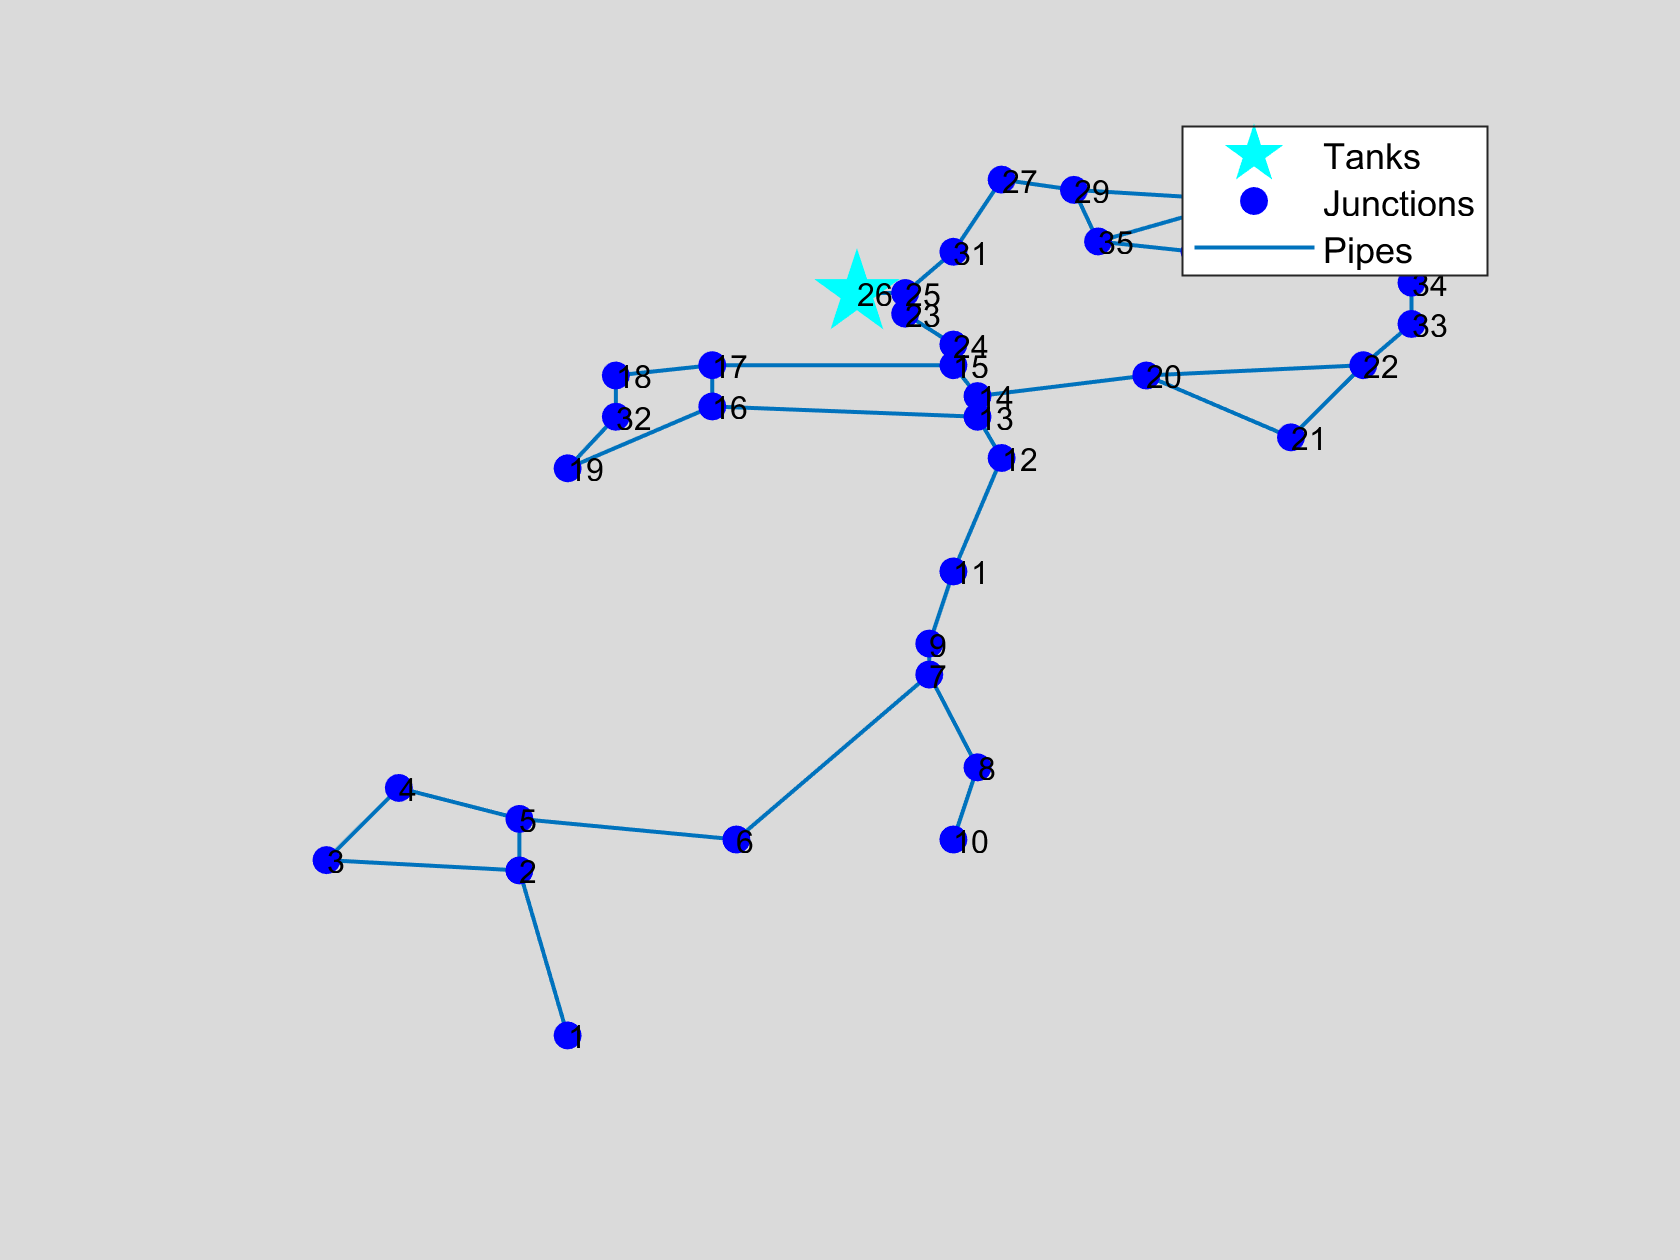

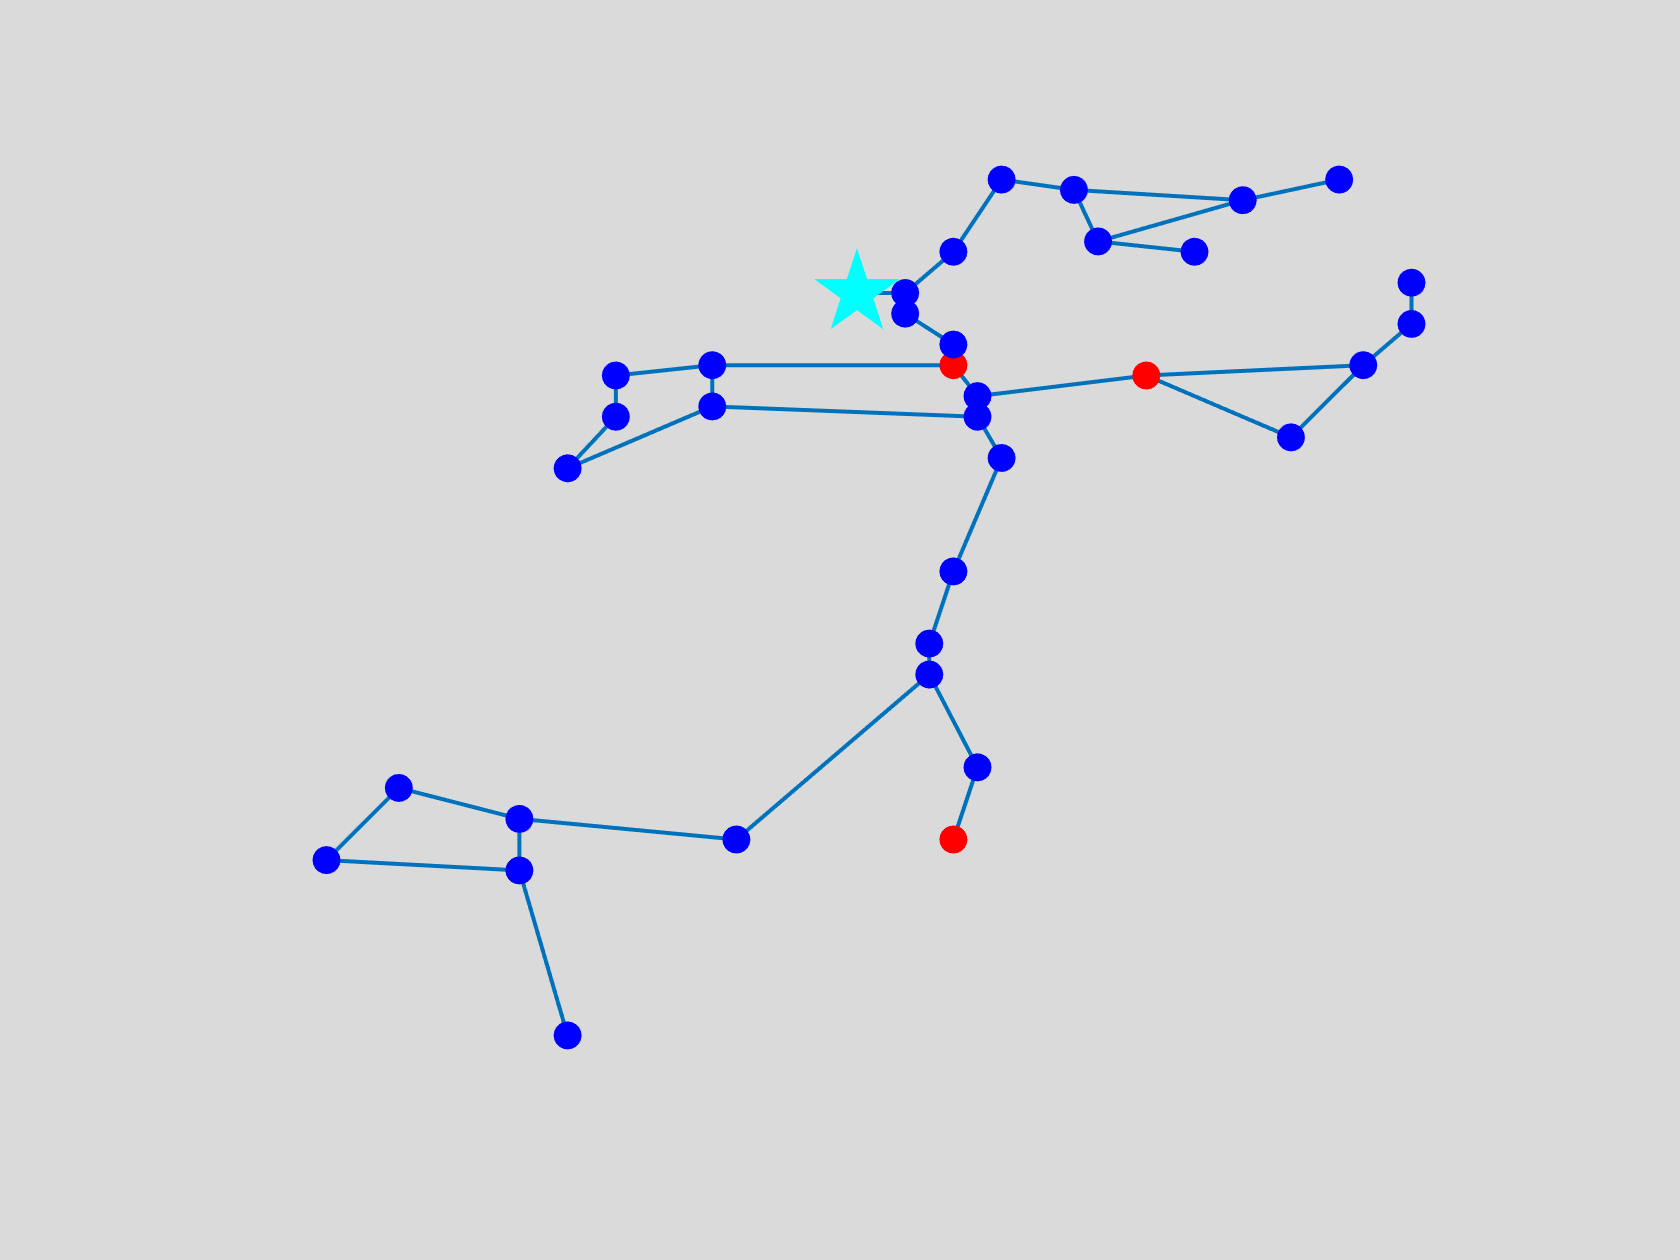

d4 = G.getLinkDiameter(4)
diameters(4) = 10
G.setLinkDiameter(diameters)
d4new = G.getLinkDiameter(4)

### **Plot a network**

% For a simple plot, use G.plot. 
G.plot;
%You can also add argurments
G.plot('nodes', 'yes', 'fontsize', 8);
% Highlight specific nodes

A =      0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

G.plot('highlightnode',{'10', '15', '20'});

g =   graph with properties:

    Edges: [40×2 table]
    Nodes: [36×0 table]


ans = 5×2 table
    EndNodes    Weight
    ________    ______

     1    2       1   
     2    3       1   
     2    5       1   
     3    4       1   
     4    5       1   


### **Preparing for Graph Theory**

**Compute connectivity matrix**

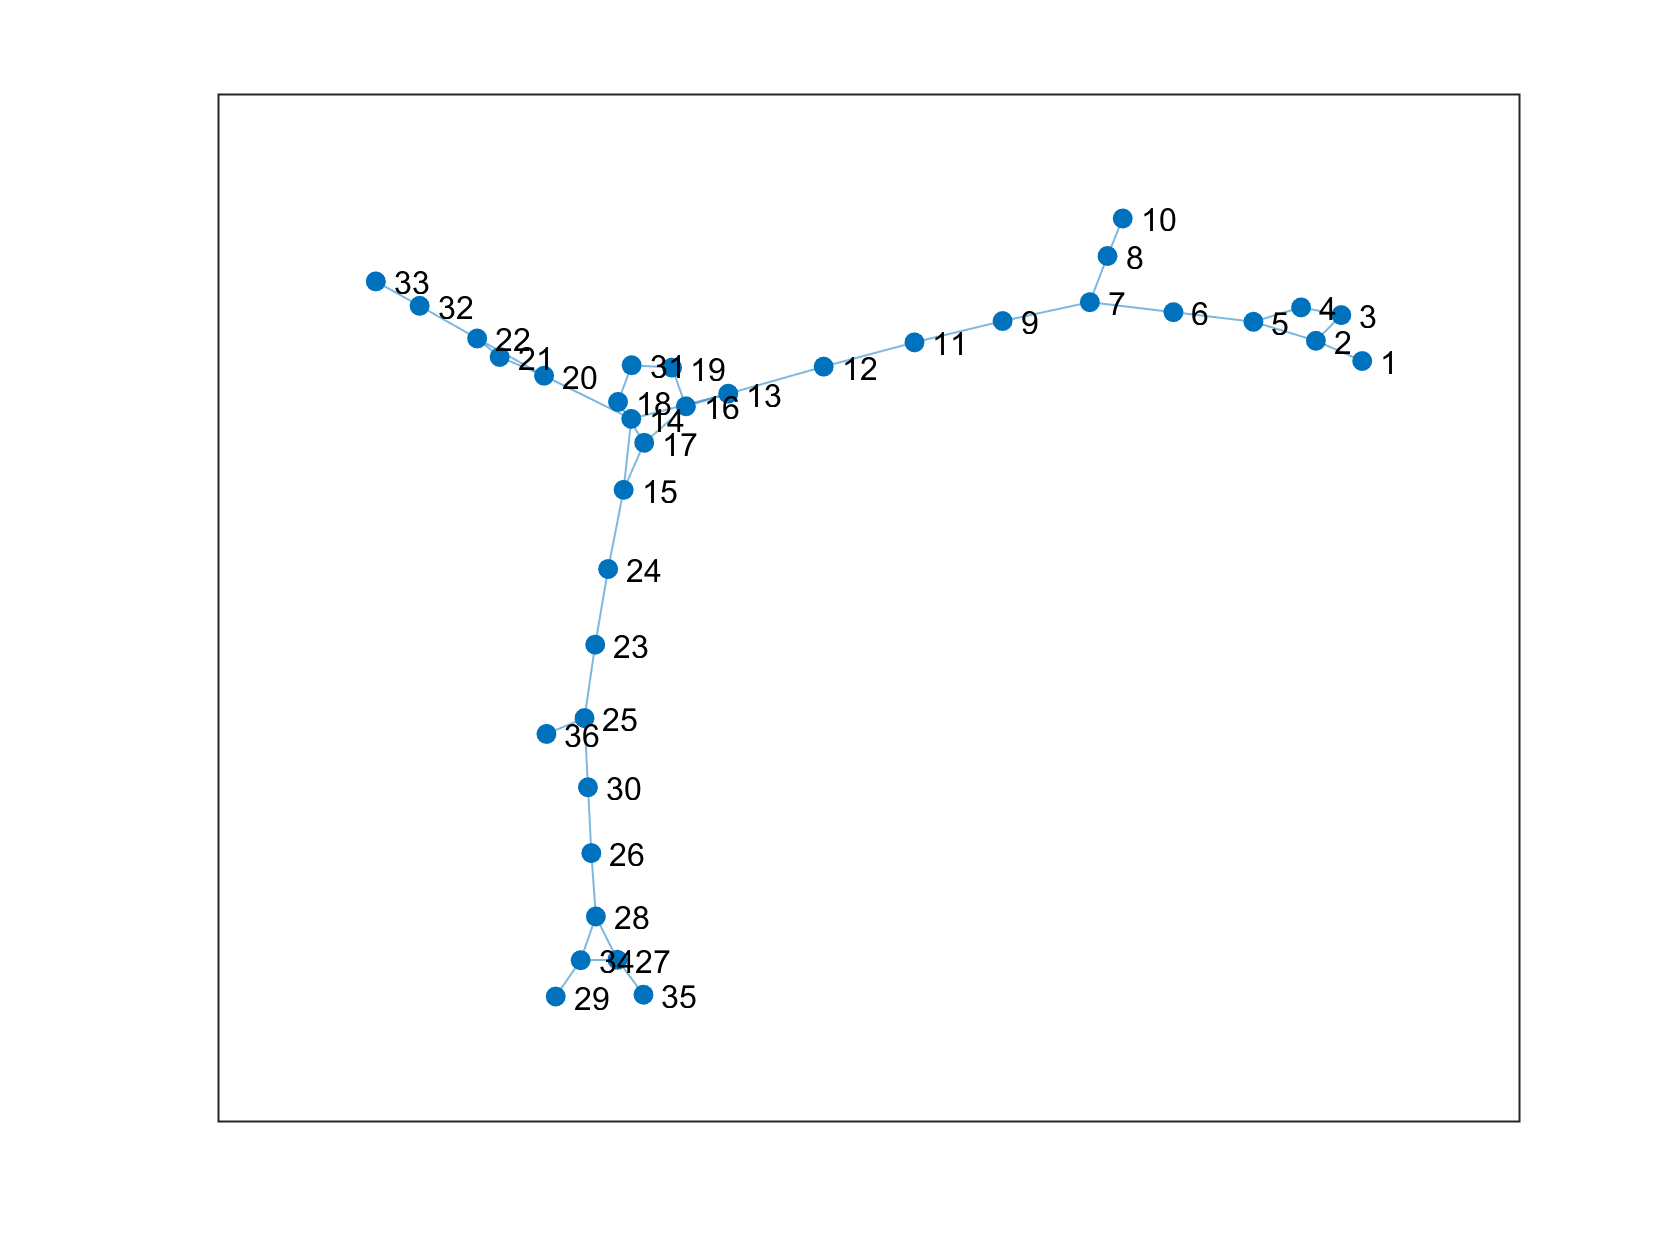

% connectivity matrix: how each node connects to other nodes
A = G.getConnectivityMatrix

**Create a network graph**

%translate the connectivity matrix into a graph structure

cdegree =      1
     3
     2
     2
     3
     2
     3
     2
     2
     1


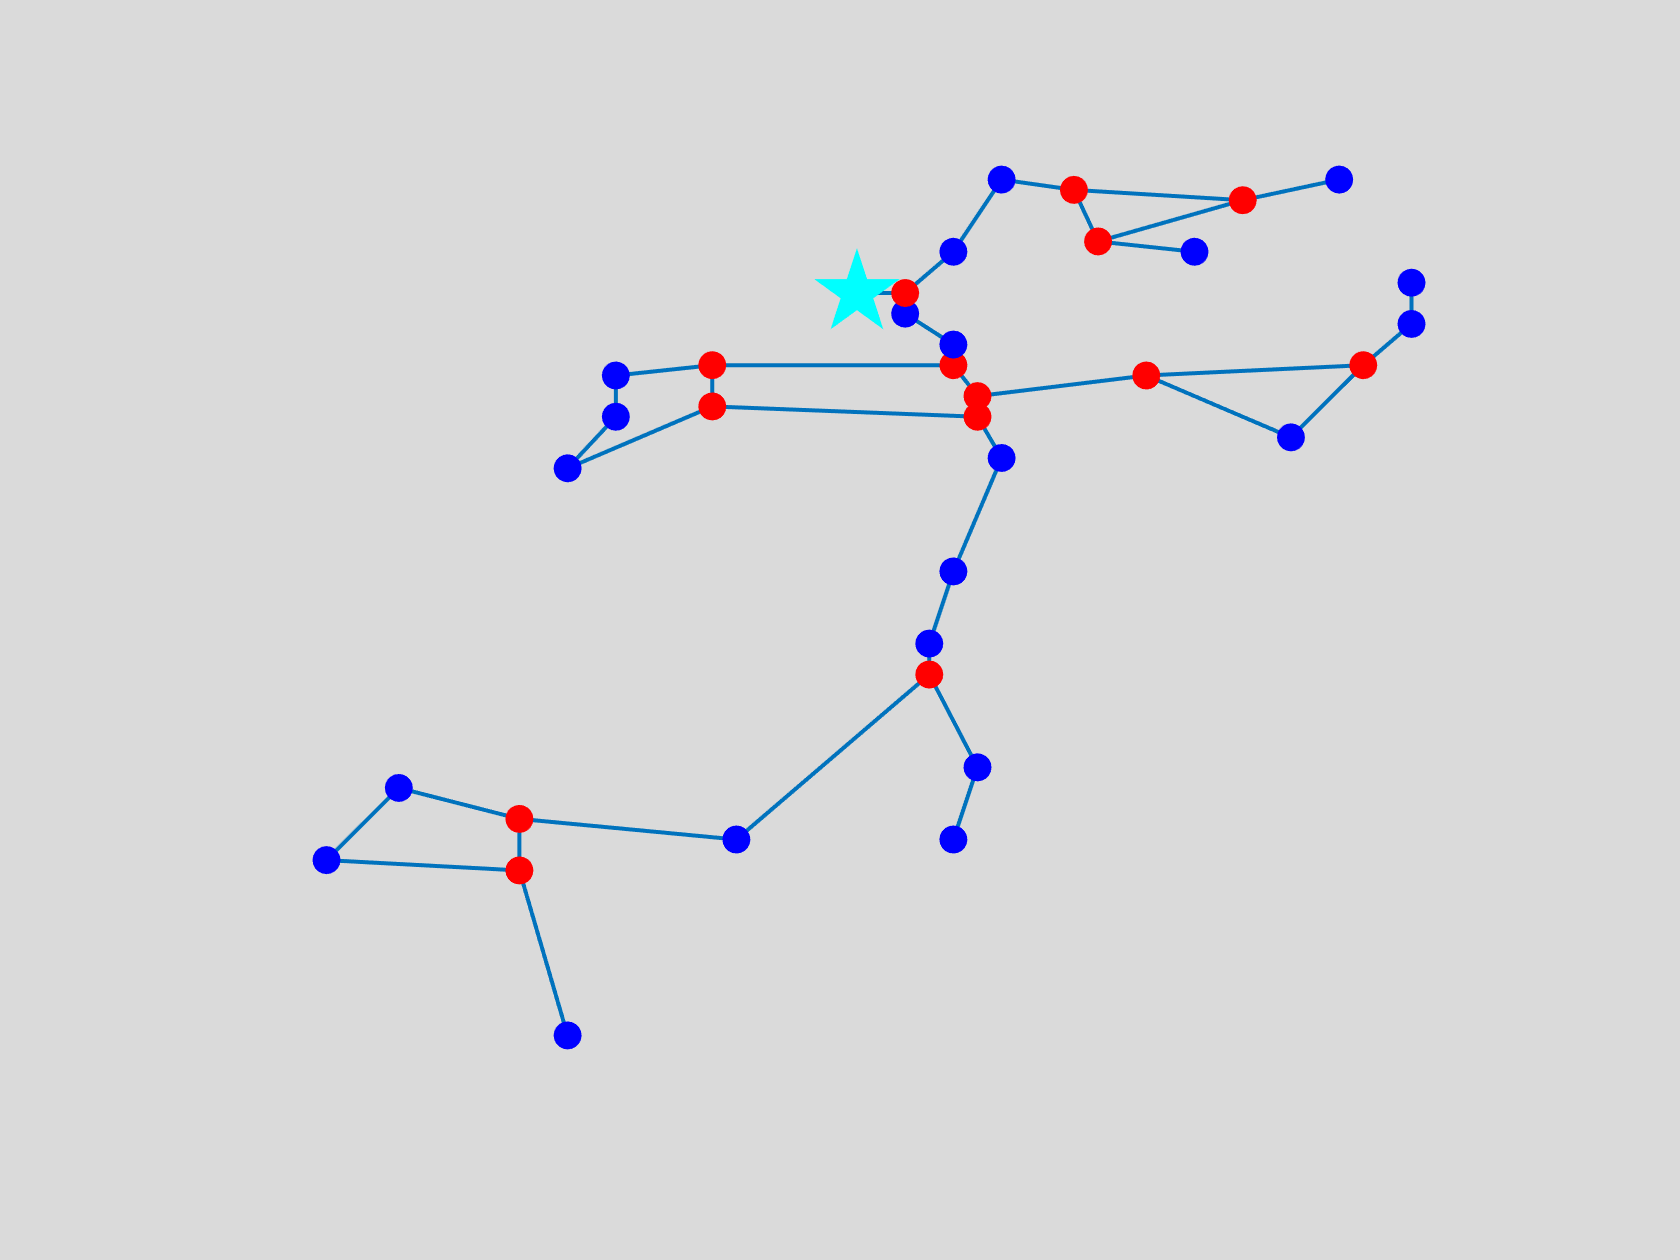

ans =   Axes with properties:

             XLim: [6.5000 60.5000]
             YLim: [-4.3000 95.3000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


g = graph(A)

g.Edges(1:5,:)
figure
plot(g)

**Compute centrality metric**

cdegree = centrality(g, 'degree')
G.plot('highlightnode',nodeID(cdegree>2))

hrs = 48

H = struct with fields:
             Time: [49×1 double]
         Pressure: [49×36 double]
           Demand: [49×36 double]
    DemandDeficit: [49×36 double]
             Head: [49×36 double]
       TankVolume: [49×36 double]
             Flow: [49×40 double]
         Velocity: [49×40 double]
         HeadLoss: [49×40 double]
           Status: [49×40 double]
          Setting: [49×40 double]
           Energy: [49×40 double]
       Efficiency: [49×40 double]


Q = struct with fields:
            Time: [49×1 double]
     NodeQuality: [49×36 double]
     LinkQuality: [49×40 double]
    MassFlowRate: [49×36 double]


### **Running your first analysis**

There are 4 ways to run a simulation using the Toolkit

- Using the batch hydraulic/quality analysis function

- Using the iterative (step-by-step) hydraulic/quality analysis function

- Using the ENepanet function binary file

- Using the command line and the binary file

The first two make calls to to the function, the last two are usually may be needed when a lot of simulations are required.

% set simulation duration at 48 hours 

P =   112.5852   88.8983  105.8867  105.8065   88.4516   76.7385   59.6289   81.2932   50.6943   72.6267   48.0835   36.2105   35.9048   40.0956   44.3498   61.6915   48.6737   83.3359   61.6743   53.0837   61.7396   40.0747   26.8263   44.2904   26.7641   70.0854   78.7495   78.7496   70.0831   44.0926   79.0029   48.7403   44.4072   78.7496   78.7495   24.5681
  113.4253   89.7384  106.7292  106.6452   89.2884   77.5531   60.3875   82.0520   51.4415   73.3856   48.8066   36.8438   36.5065   40.6815   44.9204   62.2778   49.2546   83.9179   62.2576   53.6728   62.3317   40.6668   27.3277   44.8407   27.2407   70.5647   79.2293   79.2294   70.5630   44.5703   79.5849   49.3325   44.9995   79.2293   79.2293   25.0282
  114.1375   90.4506  107.4421  107.3569   89.9994   78.2571   61.0735   82.7381   52.1238   74.0717   49.4812   37.4891   37.1415   41.3111   45.5448   62.9082   49.8833   84.5468   62.8870   54.3034   62.9631   41.2982   27.9280   45.4582   27.8325   71.1572   79.8220   7

hrs = 48 

F =   666.6240  533.8312  122.7128  105.0728   94.9928  618.7440  612.4440   17.6400  589.7640    6.3000  572.1240  528.3012  508.1412  418.2689  355.2689   87.3523   15.9677   38.7569   29.5246    4.3246   23.3954   60.4800   18.3389   -1.8211   18.2011  322.9212  336.7812  312.8412  259.9212   45.3600   23.9400   13.8600    2.5734    3.7800    1.8900  -17.0954    2.4666    3.7800    1.3134    1.2600
  666.6240  536.0402  122.2638  107.7038   99.3838  627.1040  621.9040   14.5600  603.1840    5.2000  588.6240  552.4528  535.8128  442.9776  390.9776   90.7552   -5.4752   44.4408   18.1656   -2.6344   25.5144   49.9200   15.1369   -1.5031   15.0231  382.9328  394.3728  374.6128  330.9328   37.4400   19.7600   11.4400    1.7906    3.1200    1.5600  -20.3144    2.3694    3.1200    0.7506    1.0400
  666.6240  536.7467  122.1173  108.5373  100.7773  629.7640  624.9140   13.5800  607.4540    4.8500  593.8740  560.1374  544.6174  450.9524  402.4524   91.7250  -12.1850   46.1323   14.5472   -

G.setTimeSimulationDuration(3600*hrs)

C =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.1000
    0.8000    0.7568    0.6892    0.4310    0.6982    0.6789    0.4281    0.4768    0.4282    0.4718    0.4282    0.4285    0.4286    0.4289    0.4292    0.4209    0.4340    0.4697    0.4438    0.4580    0.4550    0.4515    0.4305    0.4296    0.4310    0.4493    0.4905    0.4543    0.4906    0.4628    0.4577    0.4905    0.4903    0.4905    0.4905    0.1049
    0.8000    0.7568    0.6890    0.6157    0.6873    0.6688    0.6256    0.4569    0.6249    0.4625    0.6116    0.5816    0.5757    0.5495    0.5050    0.3543    0.3594    0.4513    0.3927    0.4233    0.4185    0.4123    0.3769    0.4568    0.3744    0.4173    0.4817    

Execute the simulation using the batch hydraulic analysis method

H = G.getComputedHydraulicTimeSeries 

T =            0
        3600
        7200
       10800
       14400
       18000
       21600
       25200
       28800
       32400


Execute the simulation using the batch quality analysis method

Q = G.getComputedQualityTimeSeries

TD = 49×1 datetime array
   24-Mar-2020 00:00:00
   24-Mar-2020 01:00:00
   24-Mar-2020 02:00:00
   24-Mar-2020 03:00:00
   24-Mar-2020 04:00:00
   24-Mar-2020 05:00:00
   24-Mar-2020 06:00:00
   24-Mar-2020 07:00:00
   24-Mar-2020 08:00:00
   24-Mar-2020 09:00:00
   24-Mar-2020 10:00:00
   24-Mar-2020 11:00:00
   24-Mar-2020 12:00:00
   24-Mar-2020 13:00:00
   24-Mar-2020 14:00:00
   24-Mar-2020 15:00:00
   24-Mar-2020 16:00:00
   24-Mar-2020 17:00:00
   24-Mar-2020 18:00:00
   24-Mar-2020 19:00:00
   24-Mar-2020 20:00:00
   24-Mar-2020 21:00:00
   24-Mar-2020 22:00:00
   24-Mar-2020 23:00:00
   25-Mar-2020 00:00:00
   25-Mar-2020 01:00:00
   25-Mar-2020 02:00:00
   25-Mar-2020 03:00:00
   25-Mar-2020 04:00:00
   25-Mar-2020 05:00:00


Plot results

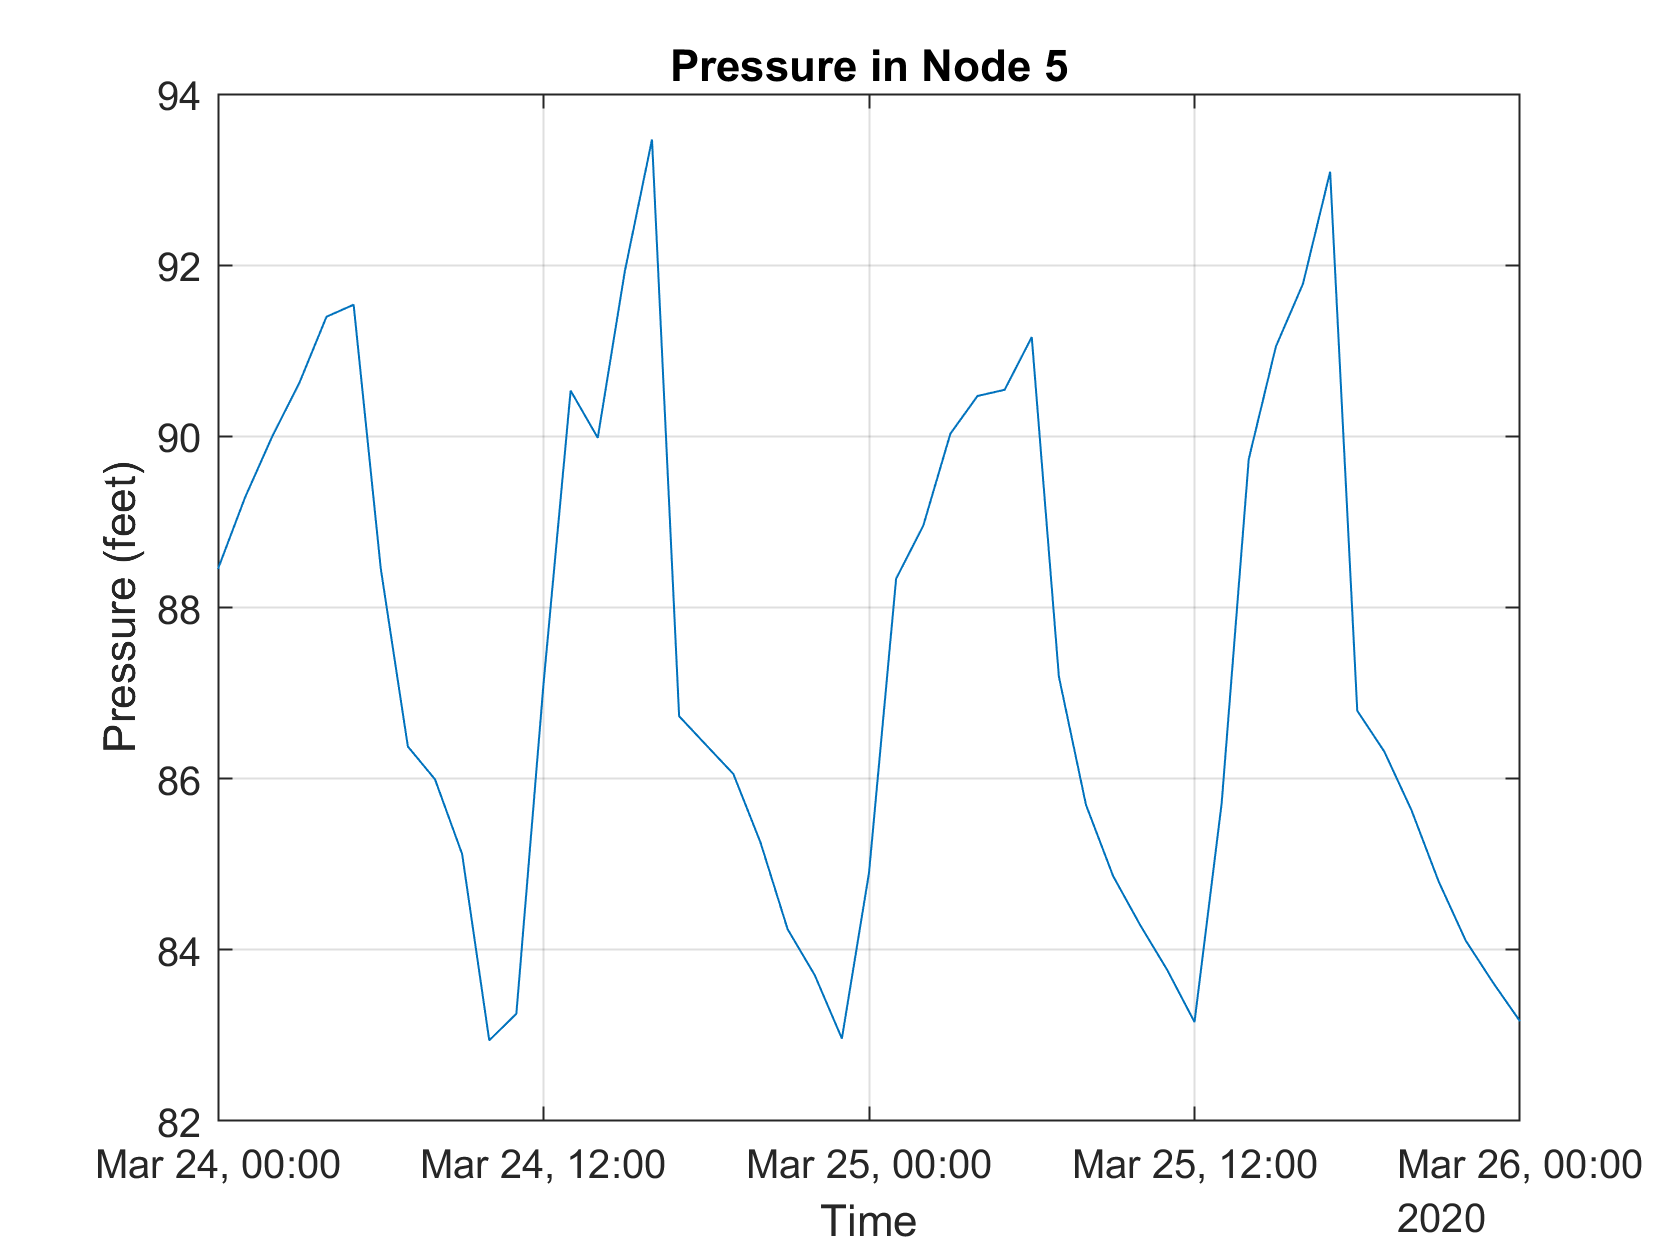

% Get pressure in meters
P = H.Pressure
F= H.Flow
C = Q.NodeQuality

% Translate time to plots 
T = H.Time

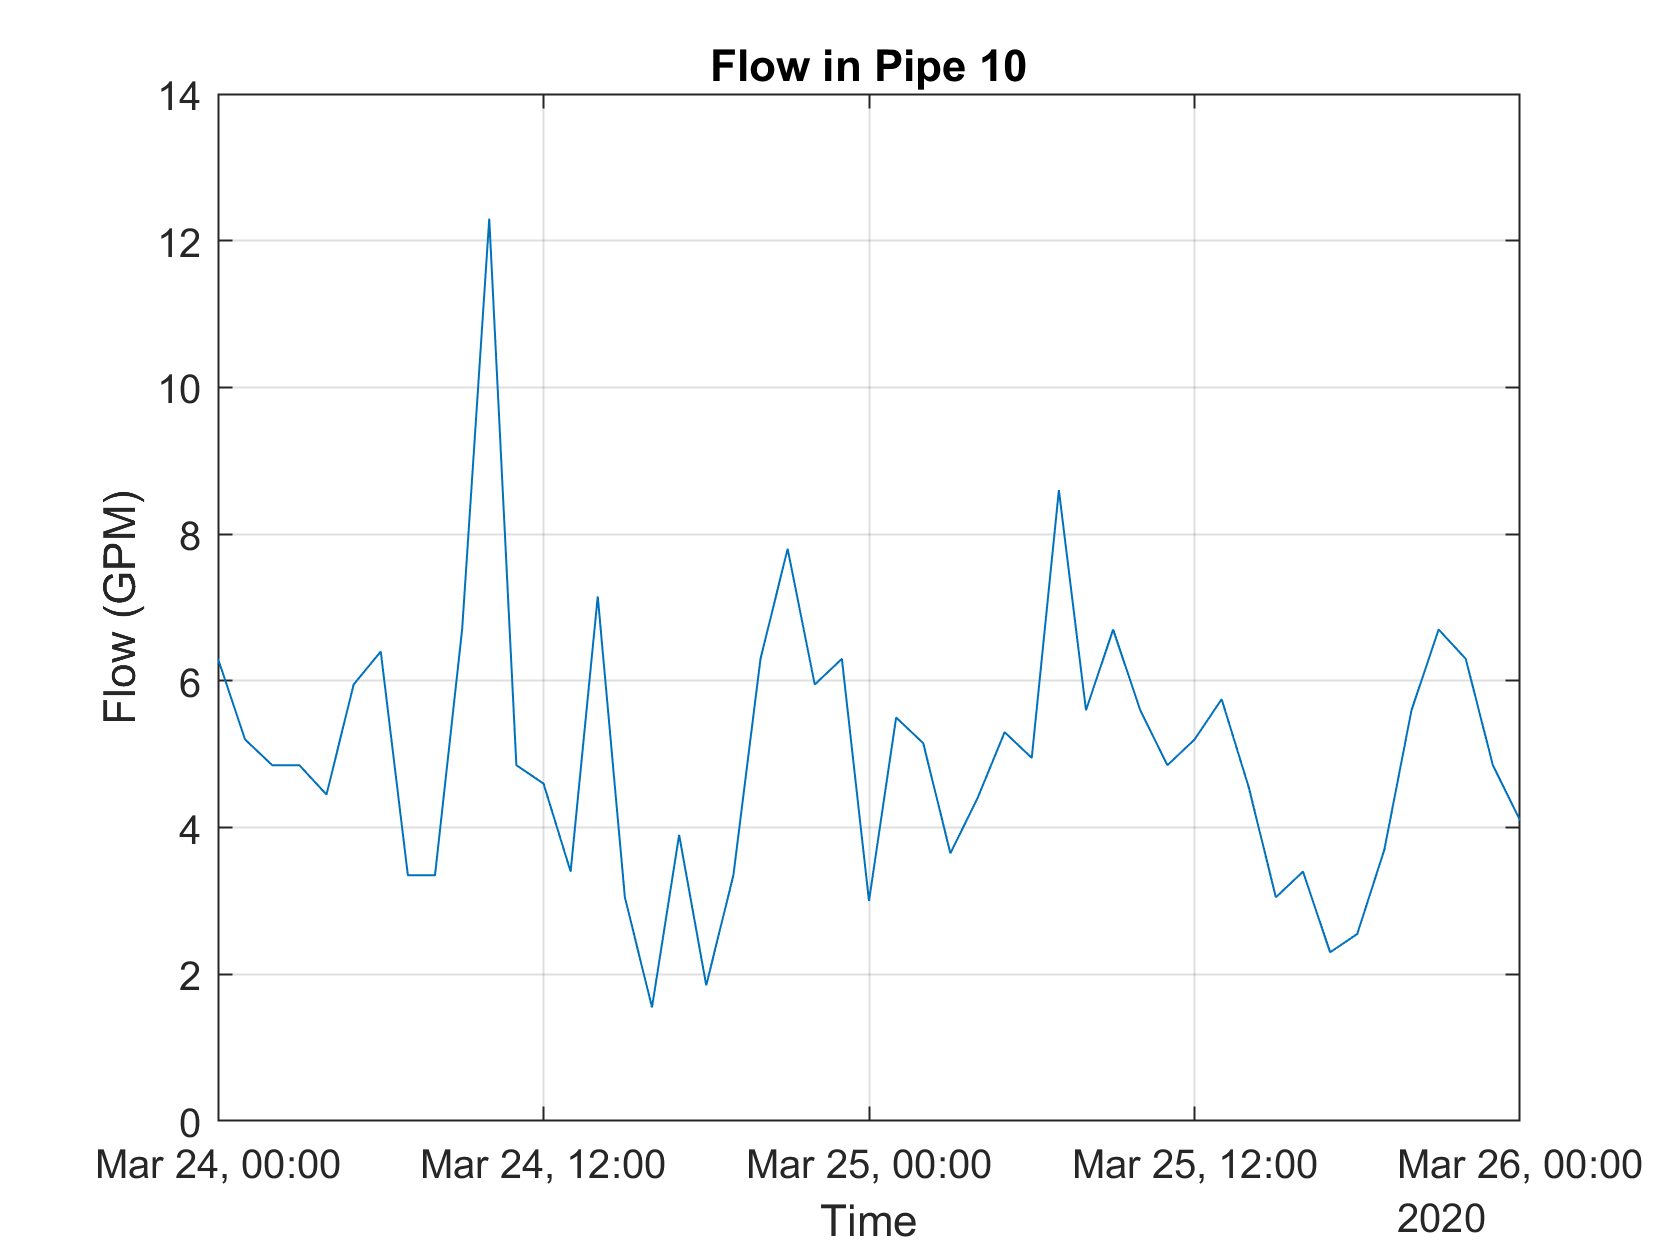

TD = datetime(2020,3,24,0,0,T) % 

% Plot
figure
plot(TD,P(:,5))
grid on
title(['Pressure in Node ',G.getNodeNameID{5}])

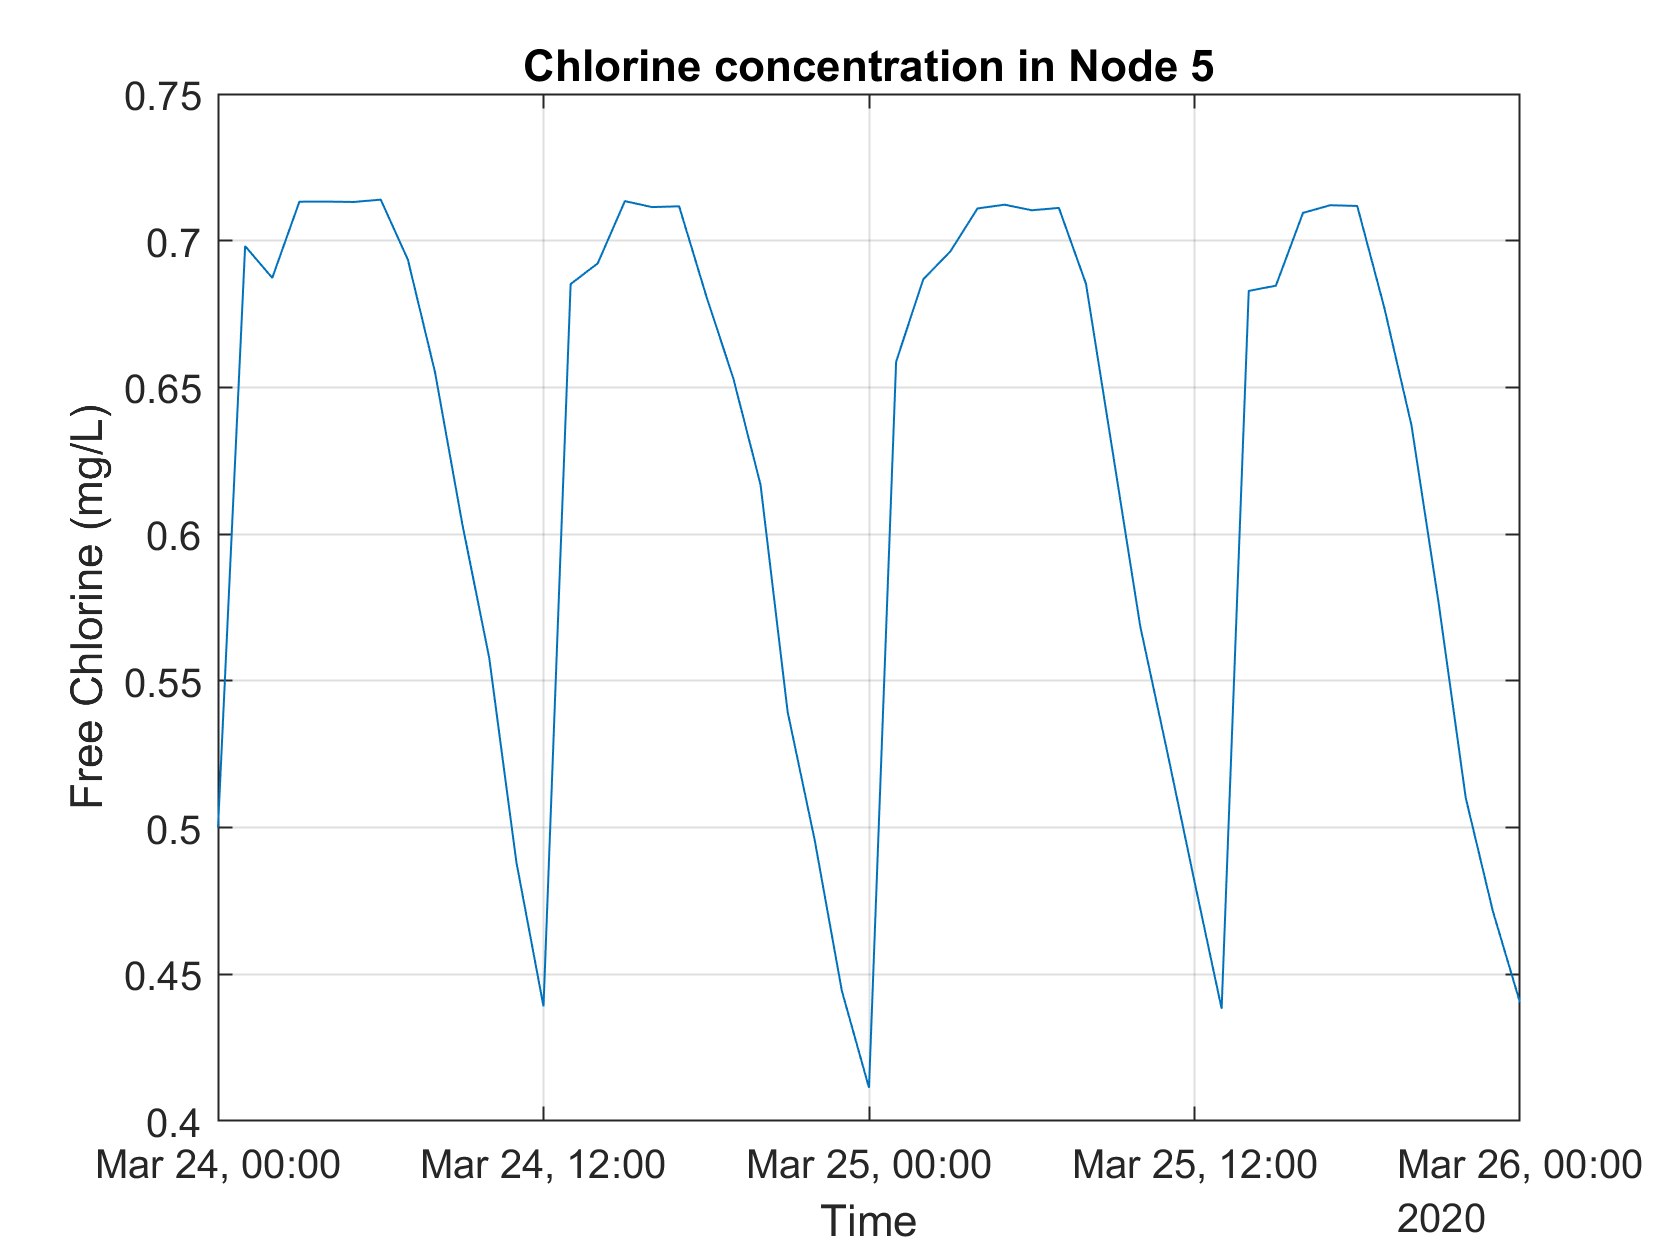

ylabel('Pressure (psi)')
xlabel('Time')

figure
plot(TD,F(:,10))
grid on
title(['Flow in Pipe ',G.getLinkNameID{10}])

ylabel('Flow (GPM)')
xlabel('Time')

figure
plot(TD,C(:,5))
grid on
title(['Chlorine concentration in Node ',G.getNodeNameID{5}])
ylabel('Free Chlorine (mg/L)')
xlabel('Time')


### Iteratively (step-by-step) hydraulic analysis

G.openHydraulicAnalysis;
G.initializeHydraulicAnalysis;

tstep=1;P2=[];T2=[];D2=[];H2=[];F2=[];

while (tstep>0)
    ttmp=G.runHydraulicAnalysis;
    P2=[P2; G.getNodePressure];
    D2=[D2; G.getNodeActualDemand];
    H2=[H2; G.getNodeHydaulicHead];

T2 =            0
        3600
        7200
       10800
       14400
       18000
       21600
       25200
       28800
       32400


    F2=[F2; G.getLinkFlows];

TD2 = 49×1 datetime array
   24-Mar-2020 00:00:00
   24-Mar-2020 01:00:00
   24-Mar-2020 02:00:00
   24-Mar-2020 03:00:00
   24-Mar-2020 04:00:00
   24-Mar-2020 05:00:00
   24-Mar-2020 06:00:00
   24-Mar-2020 07:00:00
   24-Mar-2020 08:00:00
   24-Mar-2020 09:00:00
   24-Mar-2020 10:00:00
   24-Mar-2020 11:00:00
   24-Mar-2020 12:00:00
   24-Mar-2020 13:00:00
   24-Mar-2020 14:00:00
   24-Mar-2020 15:00:00
   24-Mar-2020 16:00:00
   24-Mar-2020 17:00:00
   24-Mar-2020 18:00:00
   24-Mar-2020 19:00:00
   24-Mar-2020 20:00:00
   24-Mar-2020 21:00:00
   24-Mar-2020 22:00:00
   24-Mar-2020 23:00:00
   25-Mar-2020 00:00:00
   25-Mar-2020 01:00:00
   25-Mar-2020 02:00:00
   25-Mar-2020 03:00:00
   25-Mar-2020 04:00:00
   25-Mar-2020 05:00:00


    T2=[T2; ttmp];
    tstep=G.nextHydraulicAnalysisStep;
end

G.closeHydraulicAnalysis;

**Plot results**

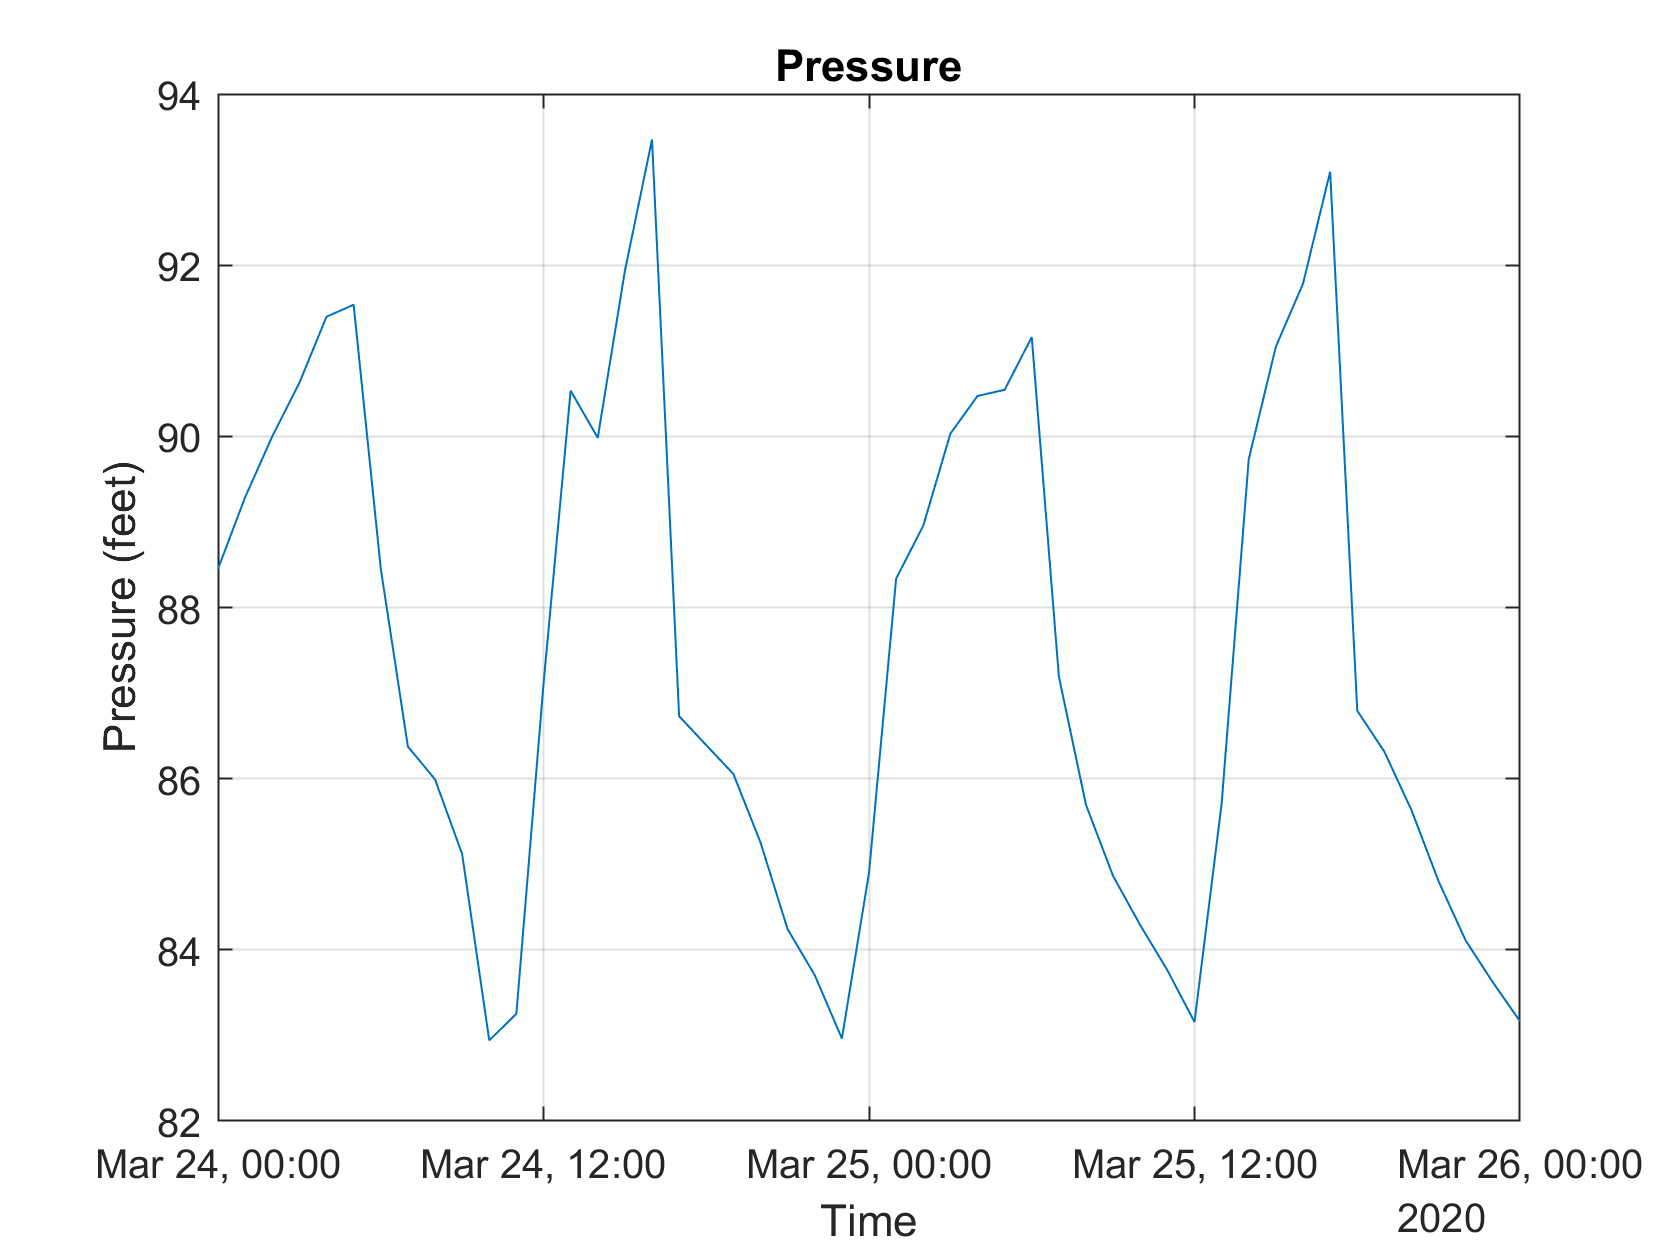

% Translate time to plots 

T2 = H.Time
TD2 = datetime(2020,3,24,0,0,T2) % 

% Plot
plot(TD2,P2(:,5))
grid on
title('Pressure')
ylabel('Pressure (psi)')
xlabel('Time')

### Iteratively (step-by-step) quality analysis

% requires solveCompleteHydraulics
G.openQualityAnalysis
G.initializeQualityAnalysis
tleft=1; QT=[];QsN=[]; QsL=[]; 
while (tleft>0)
    ttmp=G.runQualityAnalysis;

QTD = 576×1 datetime array
   24-Mar-2020 00:00:00
   24-Mar-2020 00:05:00
   24-Mar-2020 00:10:00
   24-Mar-2020 00:15:00
   24-Mar-2020 00:20:00
   24-Mar-2020 00:25:00
   24-Mar-2020 00:30:00
   24-Mar-2020 00:35:00
   24-Mar-2020 00:40:00
   24-Mar-2020 00:45:00
   24-Mar-2020 00:50:00
   24-Mar-2020 00:55:00
   24-Mar-2020 01:00:00
   24-Mar-2020 01:05:00
   24-Mar-2020 01:10:00
   24-Mar-2020 01:15:00
   24-Mar-2020 01:20:00
   24-Mar-2020 01:25:00
   24-Mar-2020 01:30:00
   24-Mar-2020 01:35:00
   24-Mar-2020 01:40:00
   24-Mar-2020 01:45:00
   24-Mar-2020 01:50:00
   24-Mar-2020 01:55:00
   24-Mar-2020 02:00:00
   24-Mar-2020 02:05:00
   24-Mar-2020 02:10:00
   24-Mar-2020 02:15:00
   24-Mar-2020 02:20:00
   24-Mar-2020 02:25:00


    QsN=[QsN; G.getNodeActualQuality];
    QsL=[QsL; G.getLinkActualQuality];
    QT=[QT; ttmp];
    tleft = G.stepQualityAnalysisTimeLeft;
end
G.closeQualityAnalysis;

Plot quality results

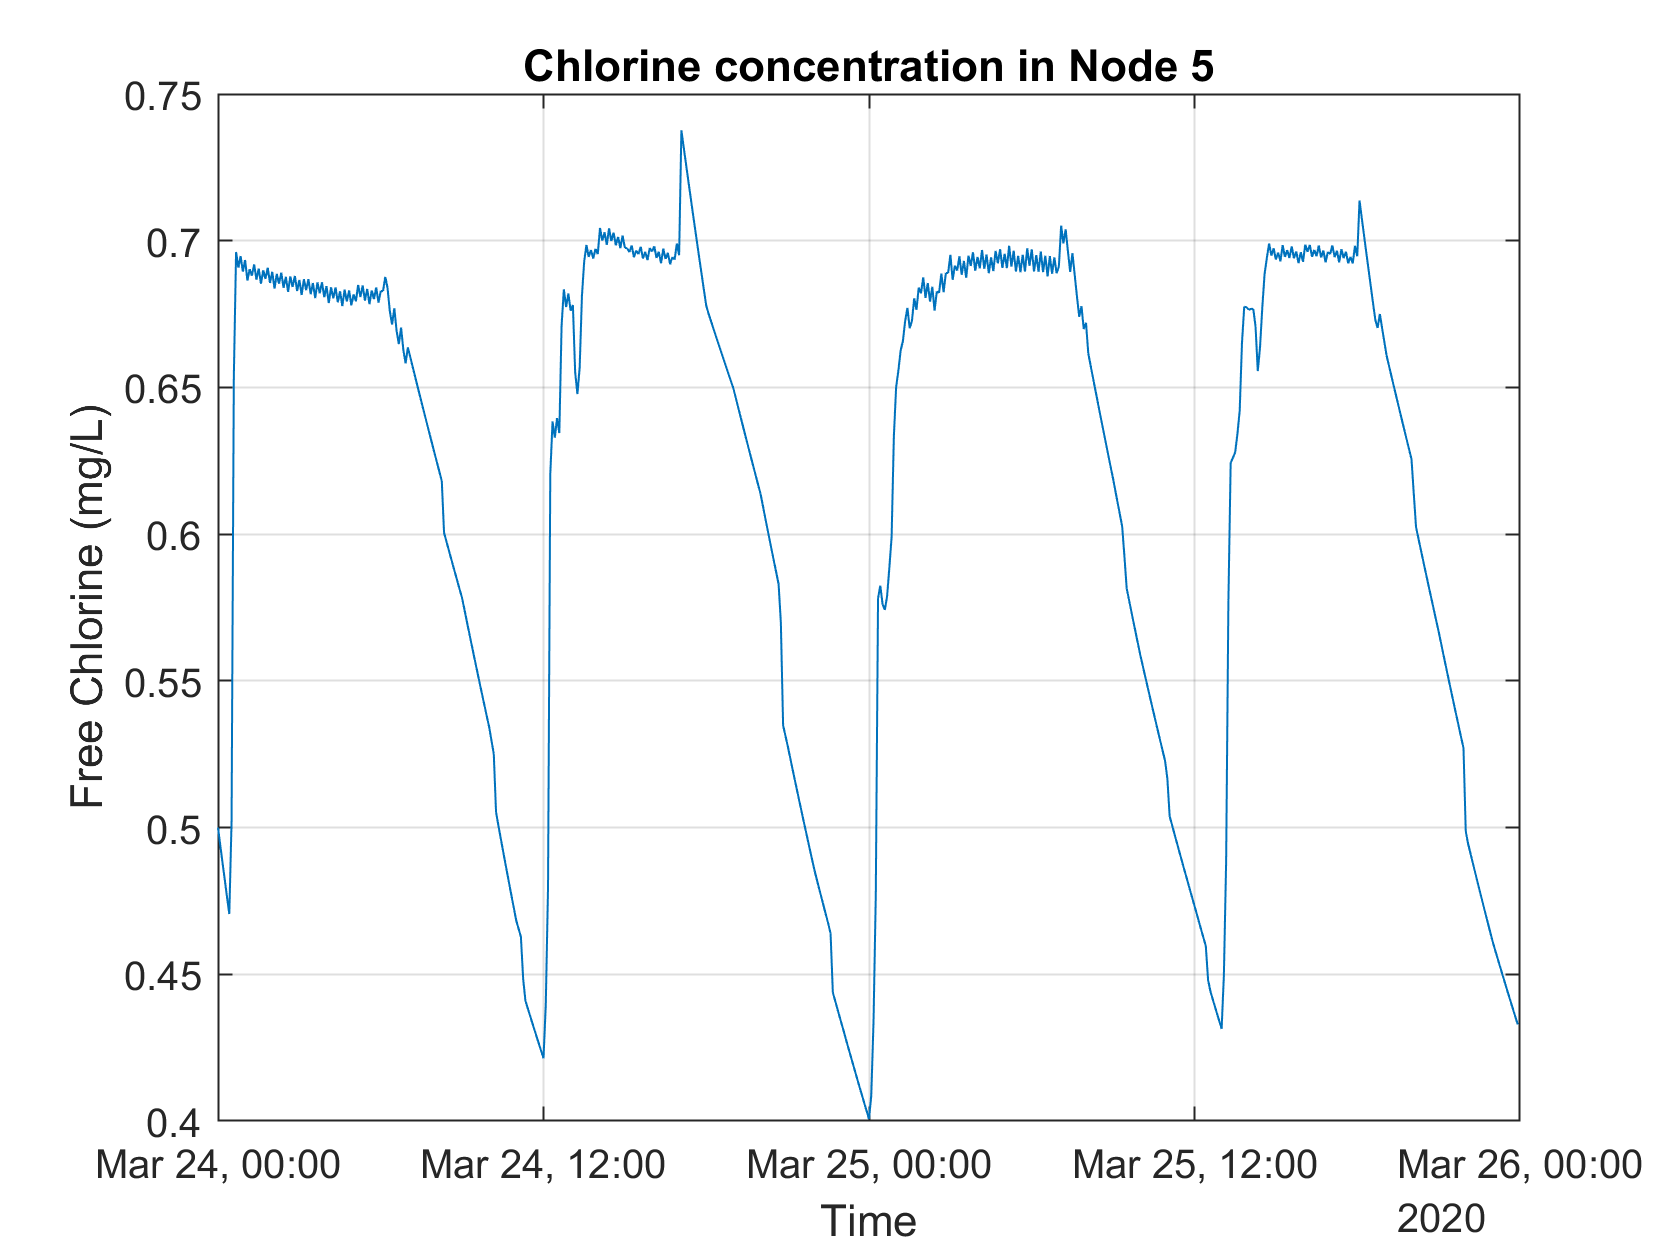

% Translate time to plots 

QTD = datetime(2020,3,24,0,0,QT) % 

% Plot
figure
plot(QTD,QsN(:,5))

B3 = struct with fields:
         BinNumberReportingPeriods: 56
                    Binmagicnumber: 516114521
                      BinLibEPANET: 20012
                    BinNumberNodes: 36
          BinNumberReservoirsTanks: 1
                    BinNumberLinks: 40
                    BinNumberPumps: 0
                   BinNumberValves: 0
             BinWaterQualityOption: 1
         BinIndexNodeSourceTracing: 0
                BinFlowUnitsOption: 1
            BinPressureUnitsOption: 0
             BinTimeStatisticsFlag: 0
          BinReportingStartTimeSec: 0
           BinReportingTimeStepSec: 3600
          BinSimulationDurationSec: 198000
                  BinProblemTitle1: 'EPANET Example Network 2                                                        '
                  BinProblemTitle2: '                                                                                '
                  BinProblemTitle3: '                                                                     

grid on

H3 = struct with fields:
              Time: [49×1 double]
          Pressure: [49×36 double]
            Demand: [49×36 double]
              Head: [49×36 double]
       NodeQuality: [49×36 double]
              Flow: [49×40 double]
          Velocity: [49×40 double]
          HeadLoss: [49×40 double]
            Status: [49×40 double]
           Setting: [49×40 double]
      ReactionRate: [49×40 double]
    FrictionFactor: [49×40 double]
       LinkQuality: [49×40 double]


title(['Chlorine concentration in Node ',G.getNodeNameID{5}])
ylabel('Free Chlorine (mg/L)')

H4 = struct with fields:
              Time: [49×1 double]
          Pressure: [49×36 double]
            Demand: [49×36 double]
              Head: [49×36 double]
       NodeQuality: [49×36 double]
              Flow: [49×40 double]
          Velocity: [49×40 double]
          HeadLoss: [49×40 double]
            Status: [49×40 double]
           Setting: [49×40 double]
      ReactionRate: [49×40 double]
    FrictionFactor: [49×40 double]
       LinkQuality: [49×40 double]


xlabel('Time')


### **Other  simulation methods**

Method using the binary result file

B3 = G.getBinComputedAllParameters 
H3 = G.getComputedTimeSeries

Method using the ENepanet function (fastest)

fid = 4

c =     '[TITLE]
     NET2 Chlorine Example
     
     
     [OPTIONS]
     AREA_UNITS  FT2
     RATE_UNITS  DAY
     SOLVER      EUL
     TIMESTEP    300
     RTOL        0.001
     ATOL        0.001
     
     
     [SPECIES]
     BULK        CL2    MG  0.01 0.001
     
     
     [COEFFICIENTS]
     PARAMETER   Kb     0.3
     PARAMETER   Kw     1.0
     
     
     [TERMS]
     Kf     1.5826e-4 * RE^0.88 / D
     
     [PIPE]
     RATE        CL2    -Kb*CL2 - (4/D)*Kw*Kf/(Kw+Kf)*CL2
     
     
     [TANK]
     RATE        CL2    -Kb*CL2
     
     
     [SOURCES]
     ;CONC/MASS/FLOW/SETPOINT   <nodeID>      <specieID>     <strength>     (<tseriesID>)
     CONC                          1             CL2           0.8
     
     
     [QUALITY]
     GLOBAL          CL2   0.5
     NODE      26    CL2   0.1
     
     [PARAMETERS]
     ;PIPE        <pipeID>      <paramID>     <value>
     ;TANK        <tankID>      <paramID>     <value>
     
     [REPORT]
     NODES  2  20  23  26
 

qual_res_MSX = struct with fields:
    NodeQuality: [576×36 double]
    LinkQuality: [576×40 double]
           Time: [576×1 double]


Q_msx = struct with fields:
    Quality: {1×36 cell}
       Time: [576×1 double]


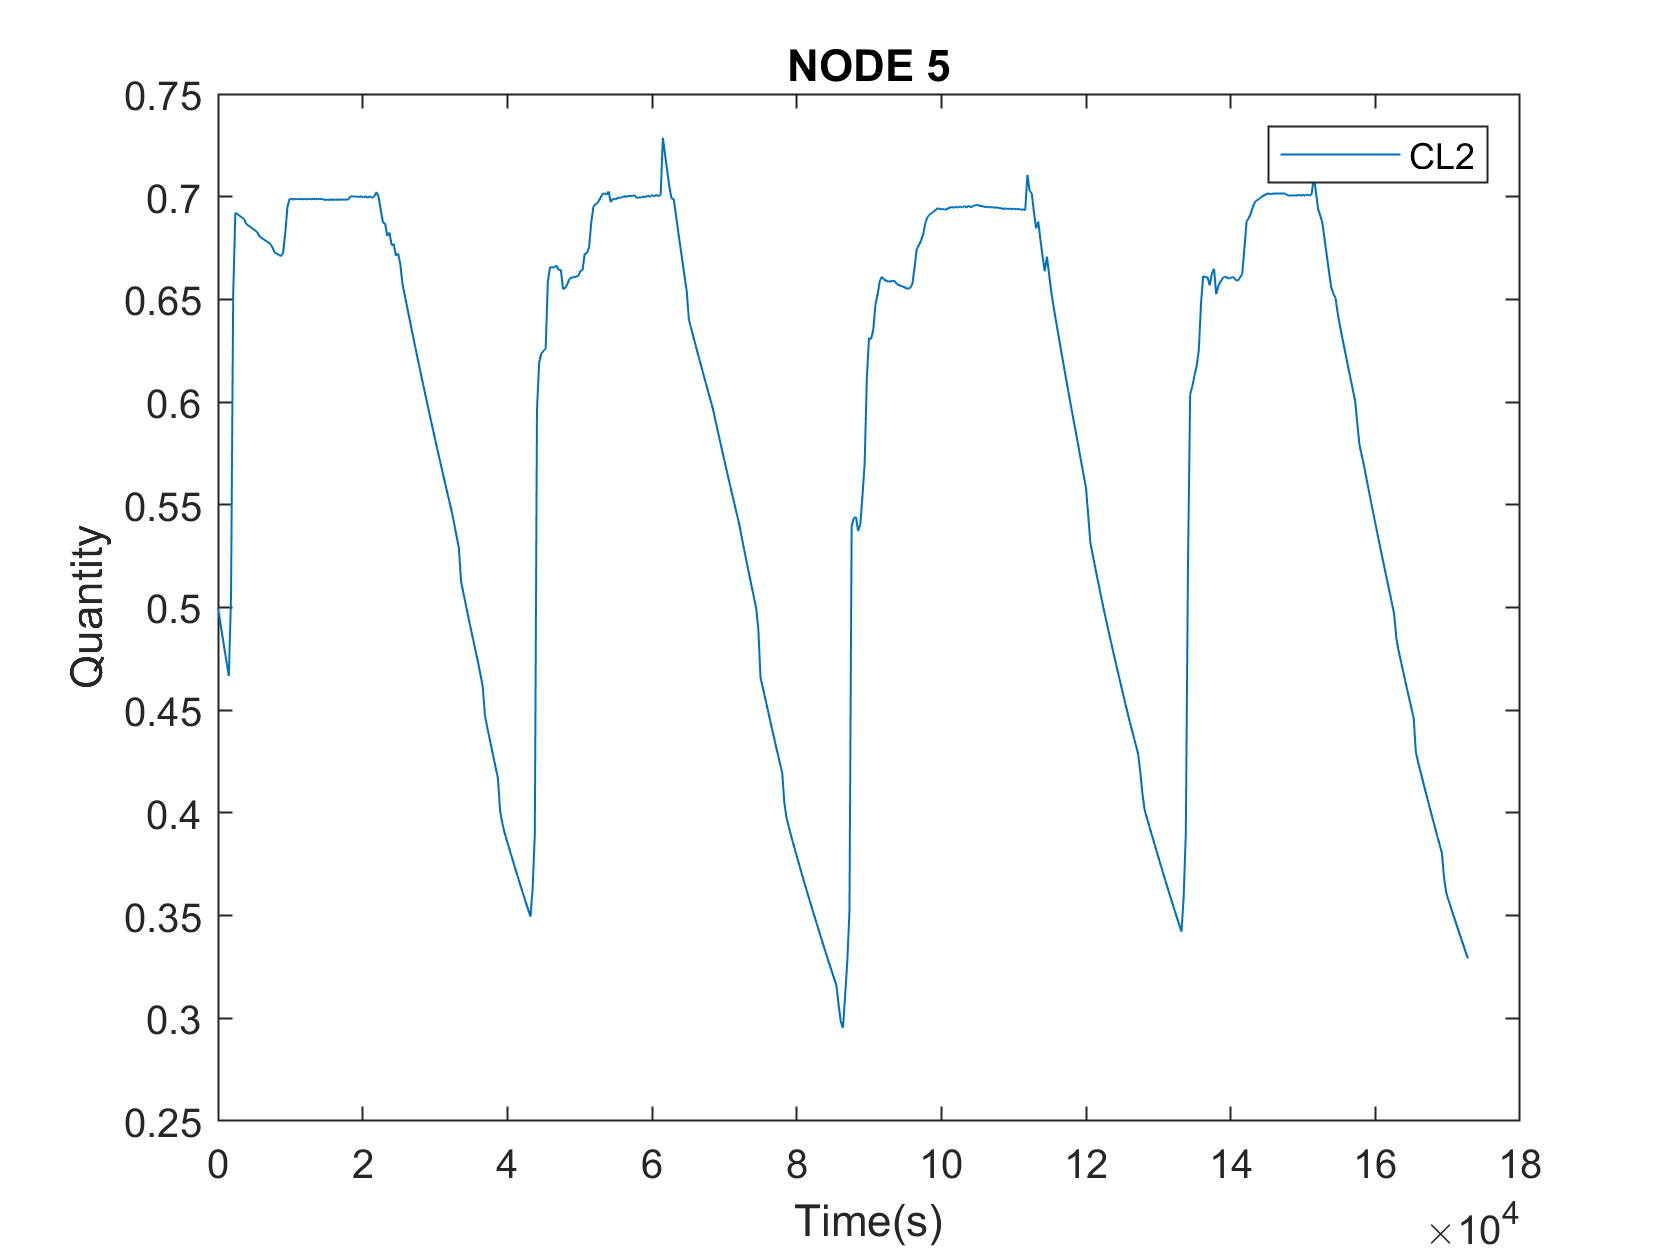

H4 = G.getComputedTimeSeries_ENepanet

### **Multi-species chemical reactions**

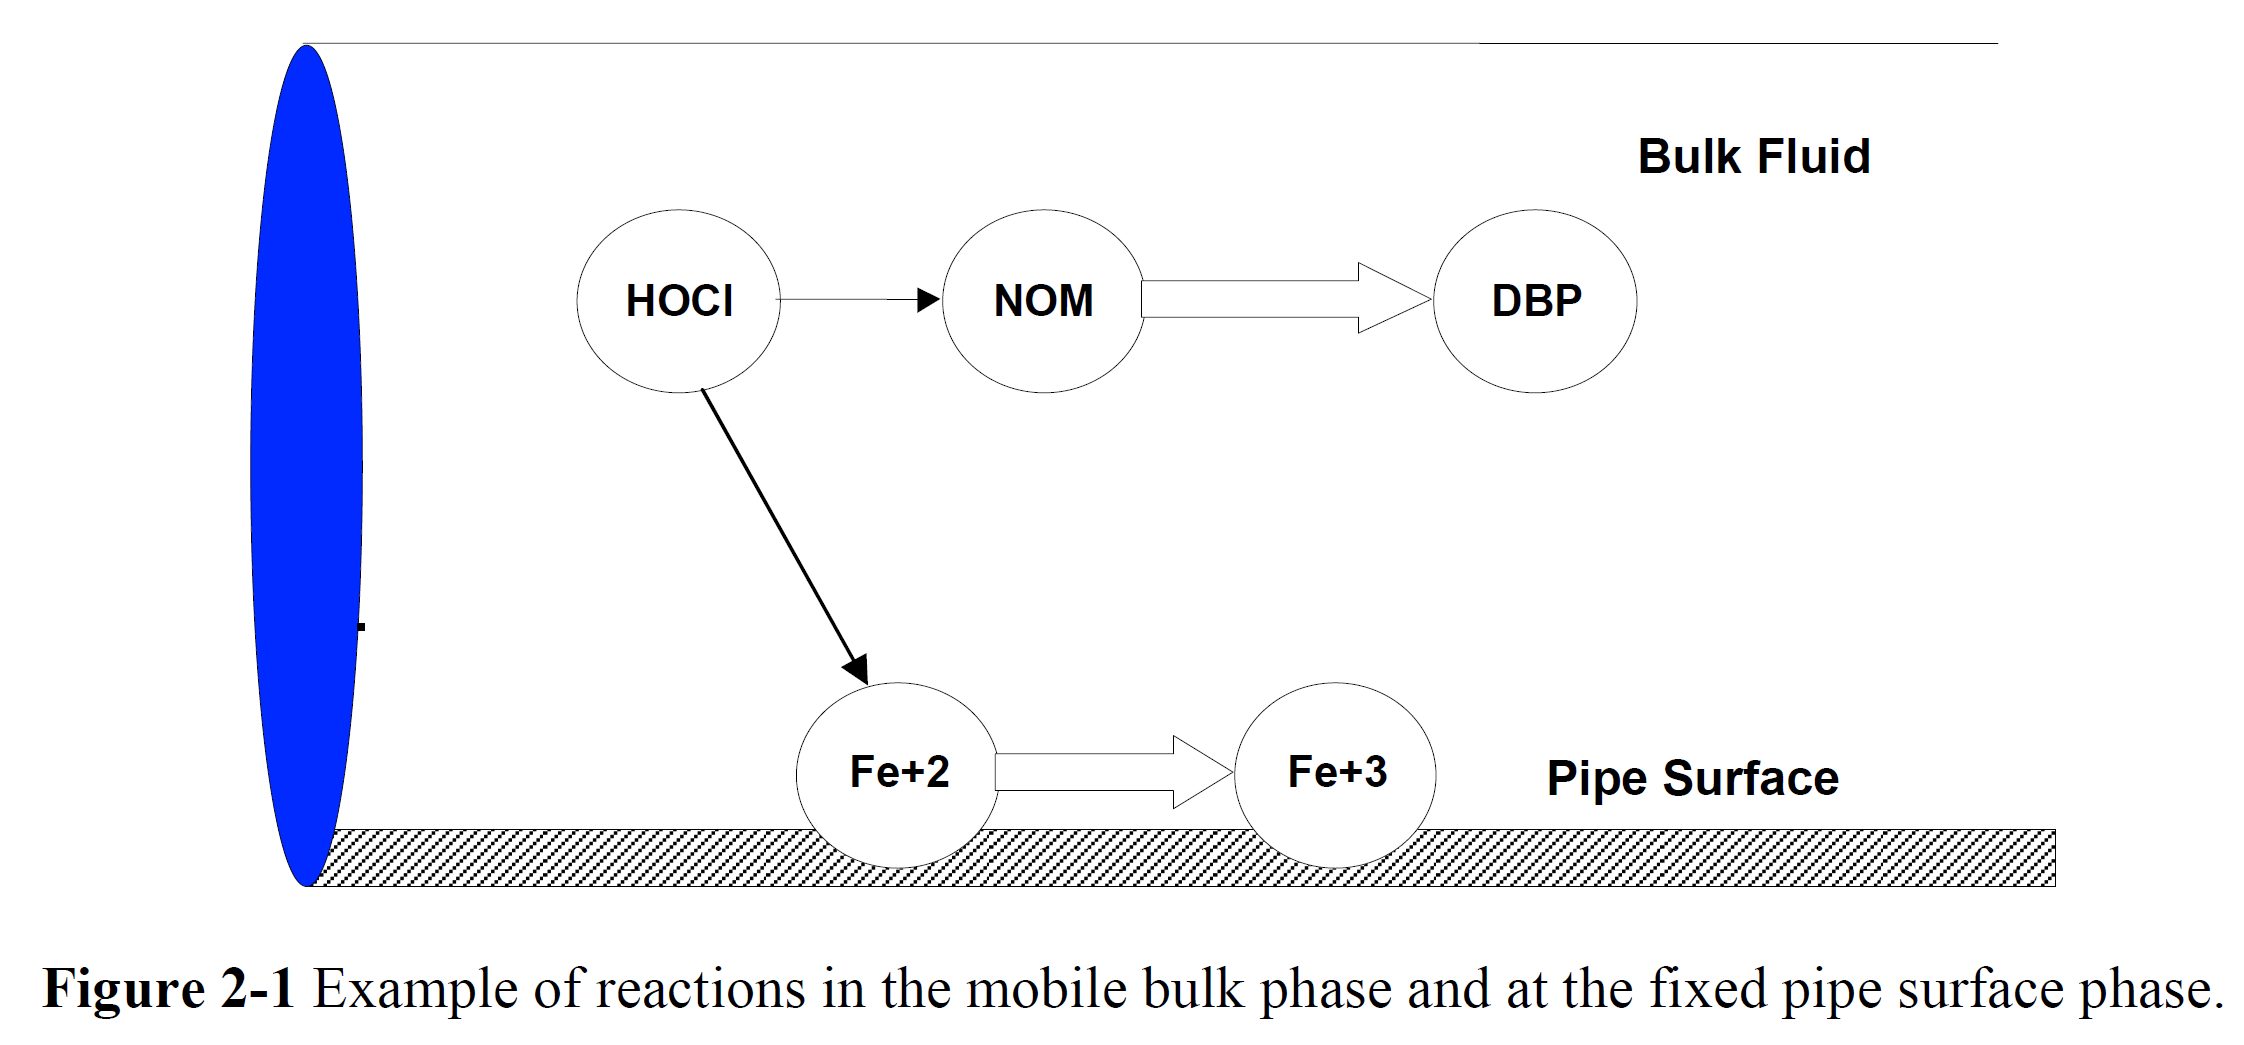

Reactions in water can be described using a set of Differential Algebraic Equations (DAE):


$$\frac{dx_b}{dt}=f(x_b,x_s,z_b,z_s)$$



$$\frac{dx_s}{dt}=g(x_b,x_s,z_b,z_s)$$



$$0=h(x_b,x_s,z_b,z_s)$$


These equations describe most of the reactions in water distribution systems. The solution methodology follows the following steps:

- Split the pipes into segments

- Solve the reaction equations for each segment

- Compute the advection (movement based on flows)

- Mix the bulk concentrations with the pipe wall concentrations 

- Recompute segmens

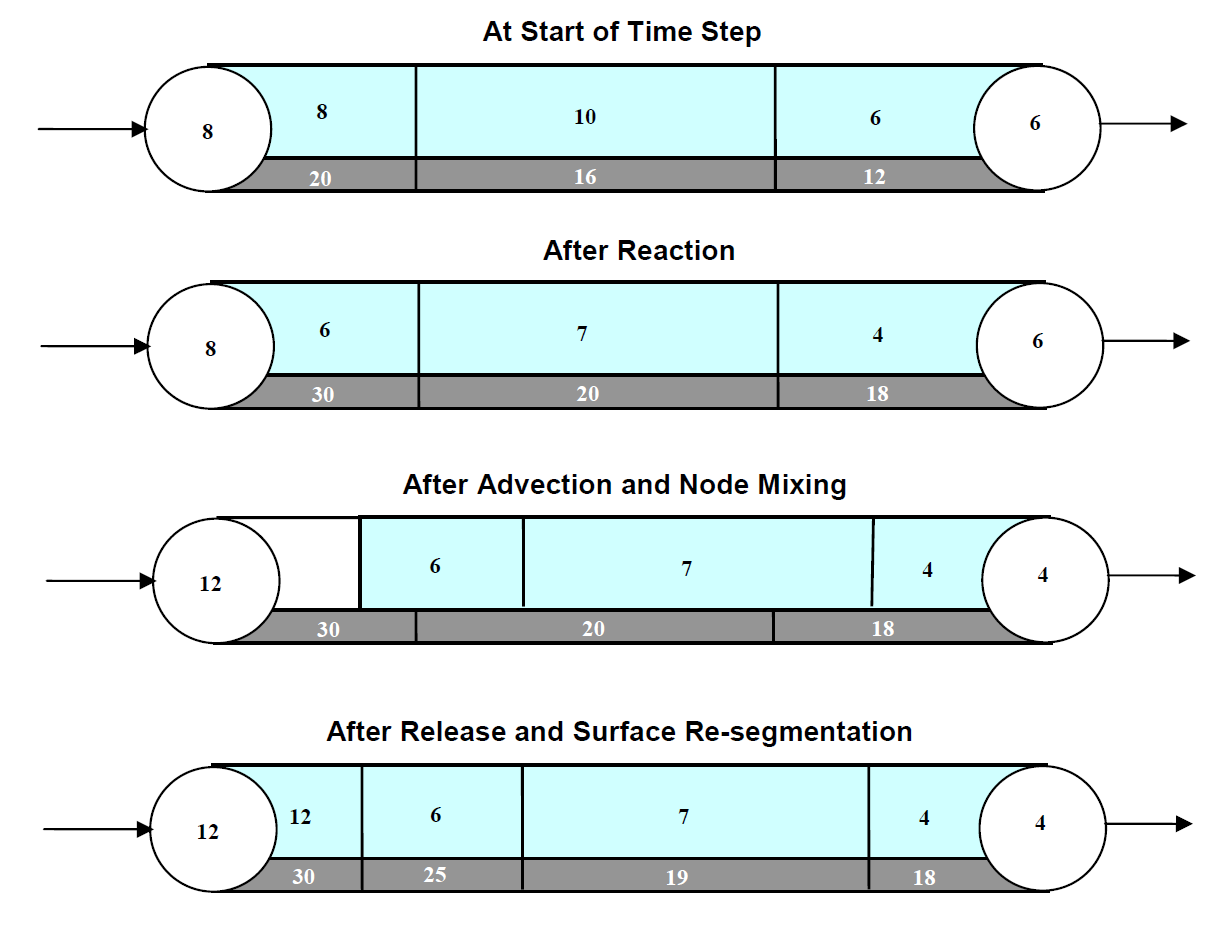

The set of diferential equations can be solved using an explicit method, e.g. **Runge-Kutta** or **Forward Euler** method.

** Chlorine reactions**

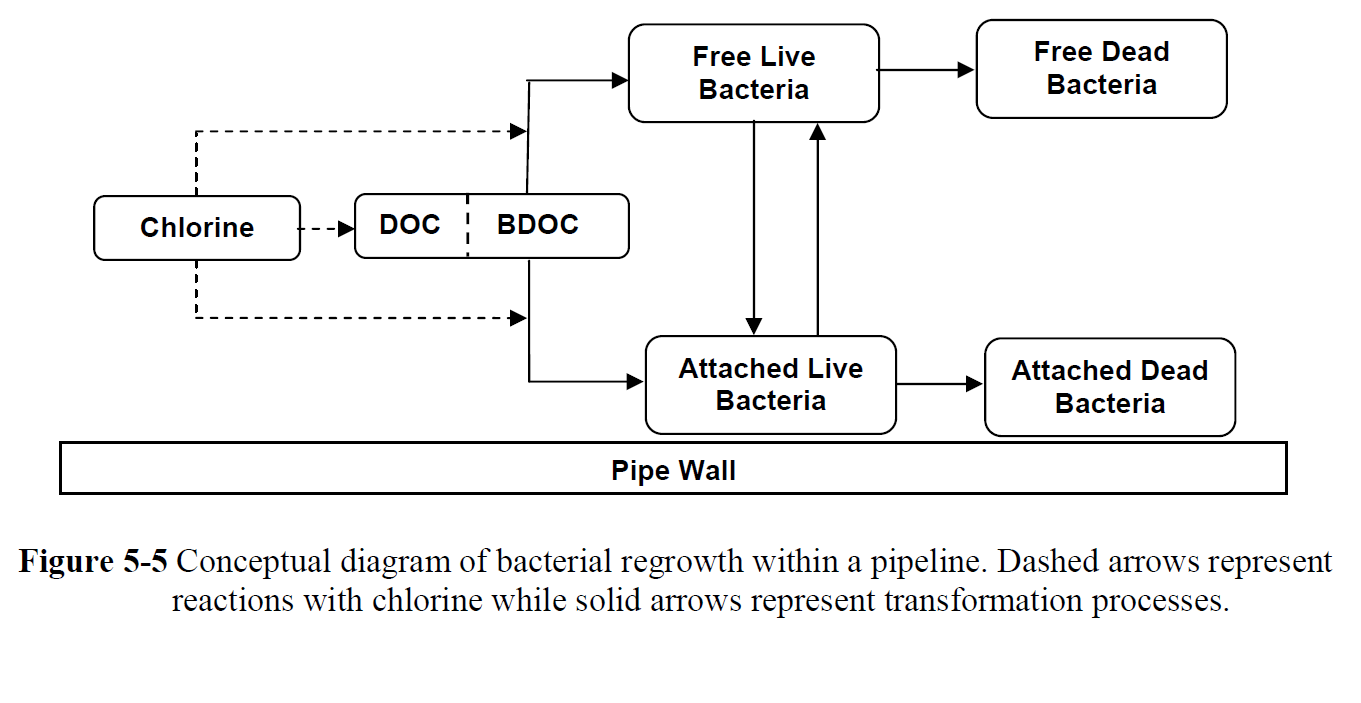

The most standard assumption is that Free Chlorine concentration is linear, i.e, 


$$\frac{dC(t)}{dt} = -k_bC(t)$$


Where $C(t)$ is the free chlorine concentration measured in $mg/L$.

% Example MSX file

sensors_names = 1×3 cell array
    {'2'}    {'3'}    {'5'}


fid = fopen('net2-cl2.msx','r')

QN = struct with fields:
    Quality: {[576×1 double]  [576×1 double]  [576×1 double]}
       Time: [576×1 double]


c = fread(fid, inf, 'uint8=>char')'

How to load an MSX file

% Load EPANET-MSX file

QL = struct with fields:
    Quality: {[576×1 double]  [576×1 double]  [576×1 double]}
       Time: [576×1 double]


G.loadMSXFile('net2-cl2.msx') % Load MSX file with reactions
qual_res_MSX = G.getMSXComputedQualitySpecie('CL2')
Q_msx = G.getMSXComputedQualityNode  % Compute water quality using MSX

Plot MSX species in MATLAB Figure

G.plotMSXSpeciesNodeConcentration(5,1)

**Another example**

% Get quality of specific nodes.
sensor_index = [2, 3, 5];

MSX_comp = struct with fields:
    NodeQuality: [576×36 double]
    LinkQuality: [576×40 double]
           Time: [576×1 double]


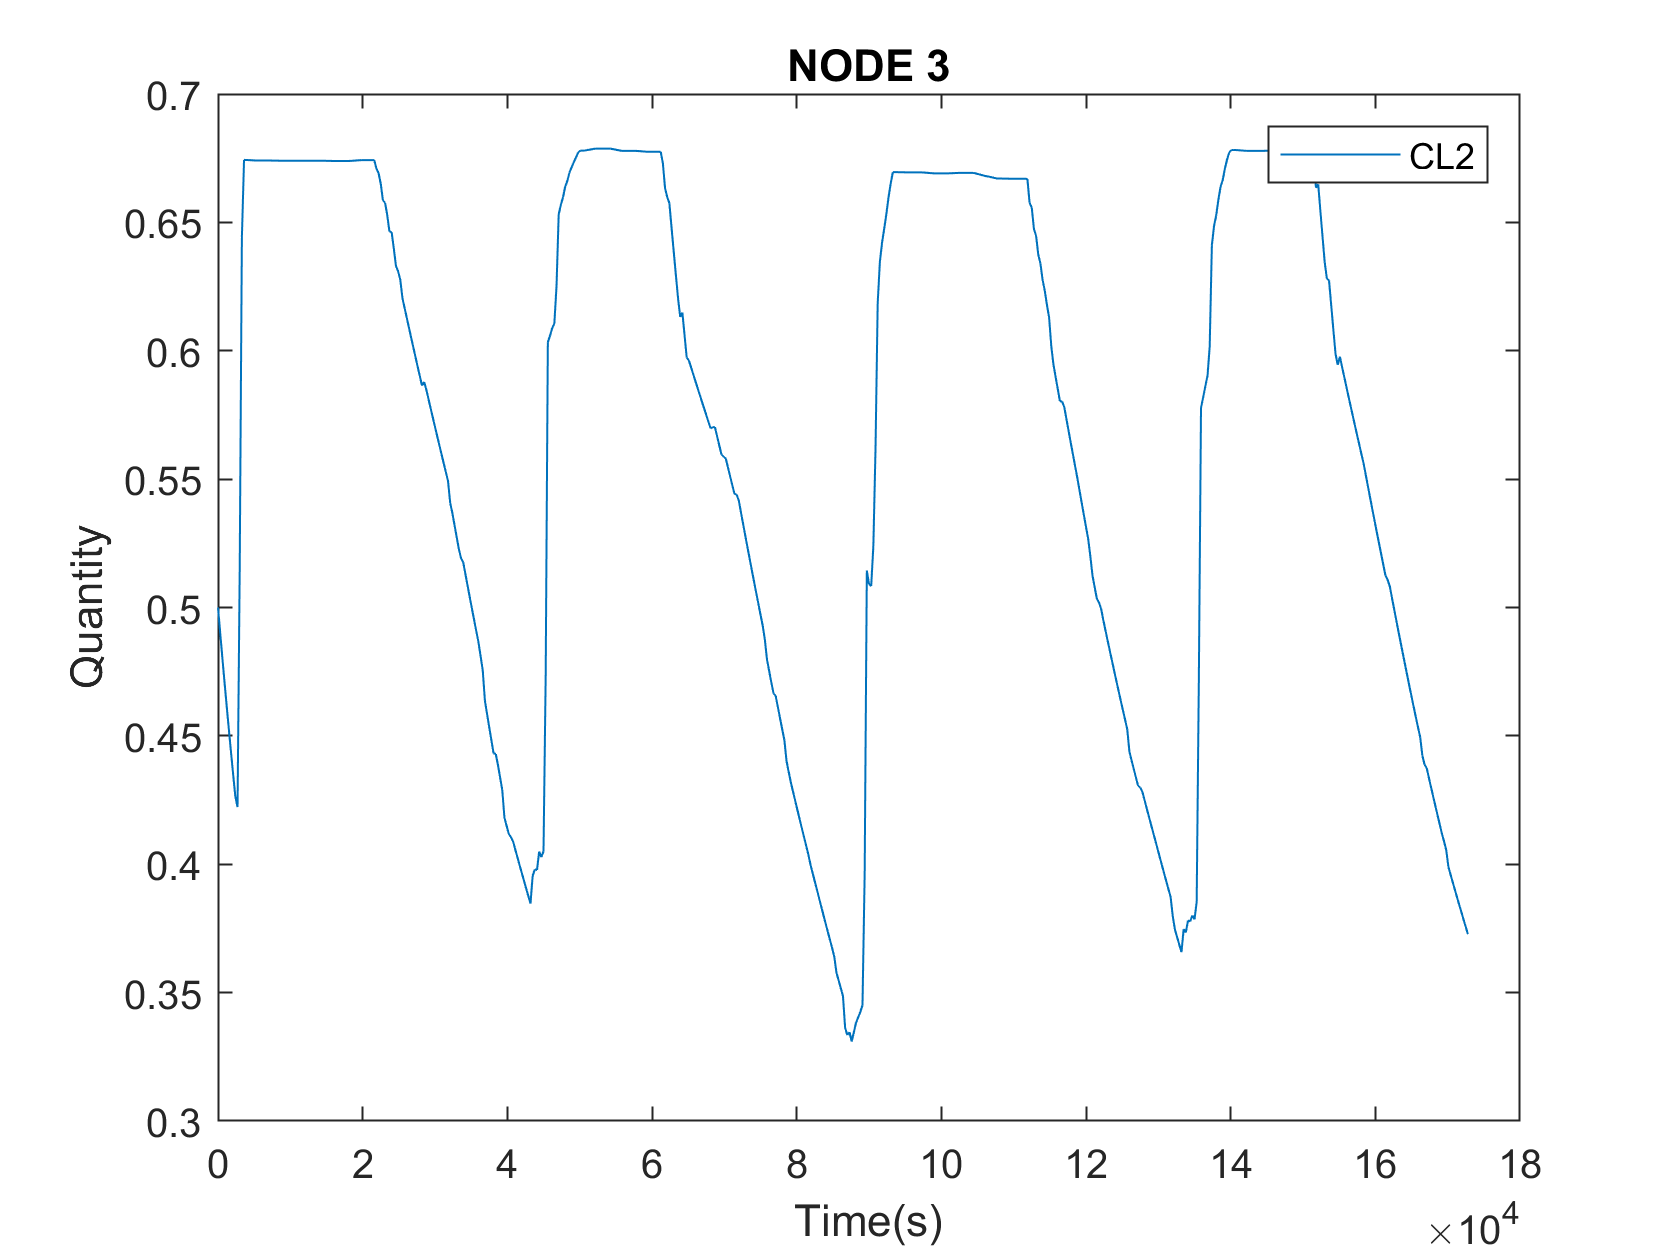

sensors_names = G.getNodeNameID(sensor_index)
QN = G.getMSXComputedQualityNode(sensor_index)


% Get quality of specific links.
QL = G.getMSXComputedQualityLink(sensor_index)

% Get species names.
type = G.getMSXSpeciesNameID;

% Get quality for specific species type (nodes and links).
for species = type
    MSX_comp = G.getMSXComputedQualitySpecie(species{1})

npi = 39322200

end

figure
G.plotMSXSpeciesNodeConcentration(3,1)

estimated_pi = 3.1414

absolute_error = 1.6283e-04

Nnodes = 10000

Nsensors = 30

## **Monte Carlo Simulations**

**Introduction to Monte Carlo Simulations**

Monte Carlo simulation is a technique used to study how a model  responds to randomly generated inputs. It typically involves a  three-step process:

- Randomly generate “N” inputs (sometimes called scenarios).

- Run a simulation for each of the “N” inputs. Simulations are run on a computerized model of the system being analyzed.

- Aggregate and assess the outputs from the simulations. Common  measures include the mean value of an output, the distribution of output values, and the minimum or maximum output value.

**Simple example: Estimate π**

For a square 1 x 1 we can fit a circle with radious 0.5 in is centre. The area of this circle should be $\pi (\frac{1}{2})^2=\frac{\pi}{4}$. If we throw random points in the square, the fraction of these points should approximate this number.

npi = 39322200

Combinations = 3.6094e+87

% Create random points within a square 1 x 1
ppi = rand(npi, 2);
% Compute distance from point [0.5, 0.5]
rpi = sqrt((ppi(:,1)-0.5).^2+(ppi(:,2)-0.5).^2);
% What fraction of points are within the 0.5 radius?
fpi = sum(rpi <= 0.5) / npi; 
estimated_pi = fpi * 4
absolute_error = abs(pi - estimated_pi)

### **When are Monte Carlo Simulations needed?**

- Computing intervals and bounds in signals, when the parameters are uncertain

- Creating scenarios for solving various selection problems which cannot be solved by integer or mixed integer programming

For instance, if you want to decide where to install some sensors

Nnodes = 10000
Nsensors = 30
Combinations = nchoosek(Nnodes,Nsensors)

For reference, $10^{78} - 10^{82}$ are the **atoms in the known universe!**

MEX configured to use 'MinGW64 Compiler (C)' for C language compilation.

To choose a different language, select one from the following:
 mex -setup C++ 
 mex -setup FORTRAN
